# Hard Disk Drive ILC Example

Iterative Learning Control

Tutorial:  2022 ASPE Annual Meeting

This script walks through applying various flavors of ILC to a model of a single stage hard disk drive system.  A bit of intro is given for each method before diving in, and results are compared at the end.  All results here look at the following block diagram, with the learning occurring at the reference node.

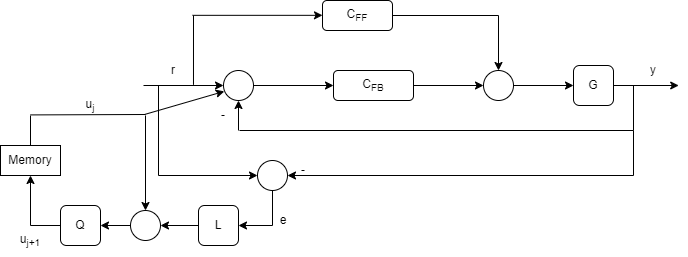

NOTE:  This script uses the Robust Control Toolbox to handle uncertainty and solve $H_\infty$ optimal ILC problems.  You will have to comment out some of this if you do not have that toolbox.

## System Modeling

### Plant Modeling

This section develops the system model for the HDD that will be used moving forward.  Not that while we are starting with an analytical model here for convenience (and so as to not display proprietary data), the approach will work the same for measured frequency responses.

Assume a plant of the form $P(s) = \frac{\prod_{i=1}^4s^2+2\zeta_i\omega_is+\omega_i^2}{{\prod_{j=1}^4s^2+2\zeta_j\omega_js+\omega_j^2}$.  

%HDD Problem
wv1 = 135;
wv2 = 5500;
wv3 = 8640;
wv41 = 7300;
wv42 = 7650;
dv1 = 0.1;
dv2 = 0.03;
dv3 = 0.05;
dv41 = 0.03;
dv42 = 0.015;

Build the plant model.

Gv = 10;  %DC Gain
Gv1 = tf((2*pi*wv1)^2,[1 2*dv1*2*pi*wv1 (2*pi*wv1)^2]);
Gv2 = tf((2*pi*wv2)^2,[1 2*dv2*2*pi*wv2 (2*pi*wv2)^2]);
Gv3 = tf((2*pi*wv3)^2,[1 2*dv3*2*pi*wv3 (2*pi*wv3)^2]);
Gv4 = wv41^2/wv42^2*tf([1 2*dv42*2*pi*wv42 (2*pi*wv42)^2],[1 2*dv41*2*pi*wv41 (2*pi*wv41)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4;

Let's now visualize the plant model in the frequency domain.

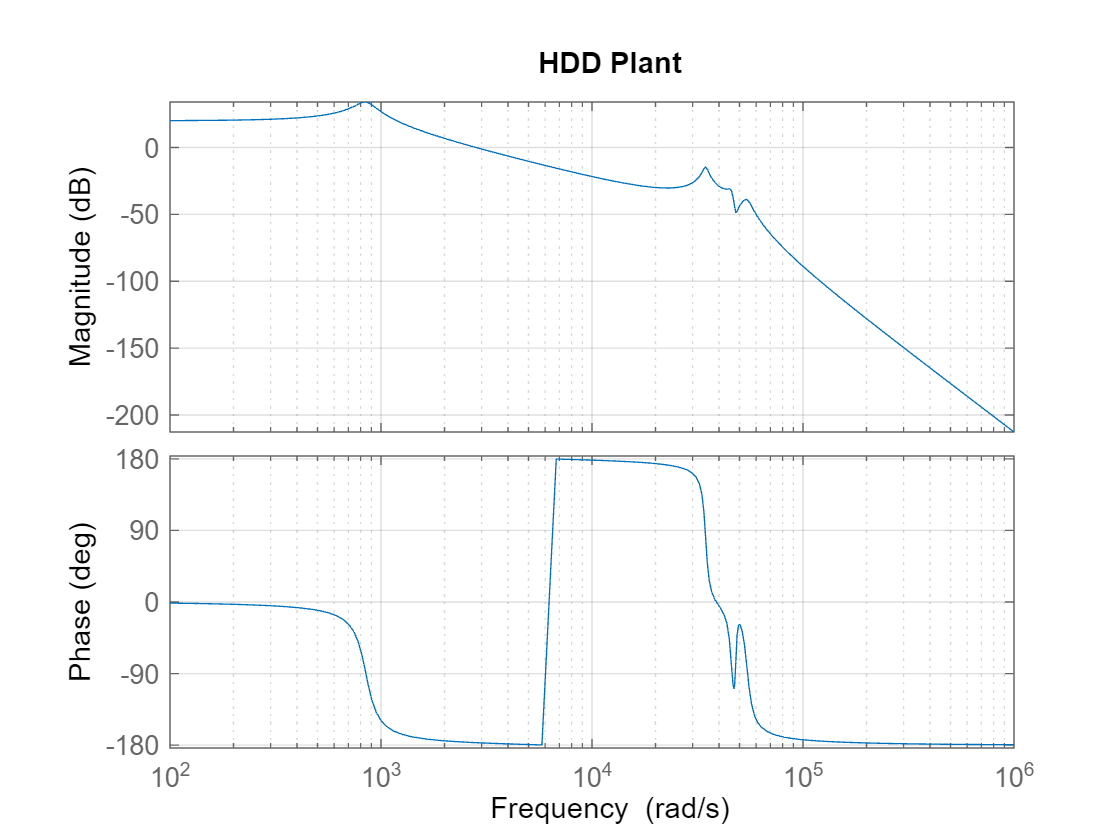

bode(VCM,{100,1e6});
title('HDD Plant')

### Controller Modeling

I will use the robust control toolbox to get a quick controller for this plant for simulation.  Of course there are many other techniques that could be used to get here; in any case we can see that this method is effective even if it is mysterious.  I will assume a sampling rate of 100 kHz.

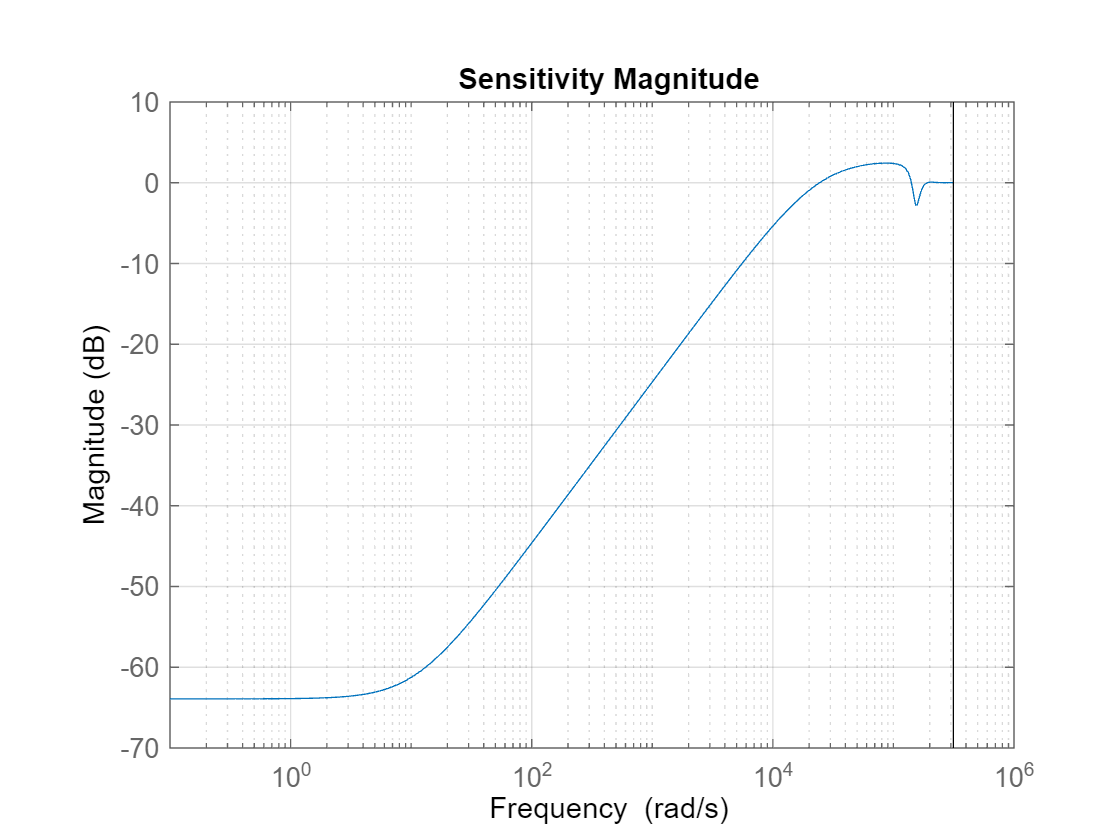

Ts = 1/100e3;
Fs = 1/Ts;
z = tf('z',Ts);
plantDT = c2d(VCM,Ts,'matched');  %Uses the matched method to create a stable plant inverse
K = mixsyn(plantDT,makeweight(1000,2000*2*pi,1/2,Ts),1/1e6,makeweight(1/3,20000*2*pi,100,Ts));  %Just getting a semi-reasonable controller to form "T"
bodemag(feedback(1,plantDT*K))
title('Sensitivity Magnitude')

G = -minreal(feedback(plantDT*K,1));  %This is the plant ILC will learn the inverse of

11 states removed.


## ILC Plant Model and Uncertainty

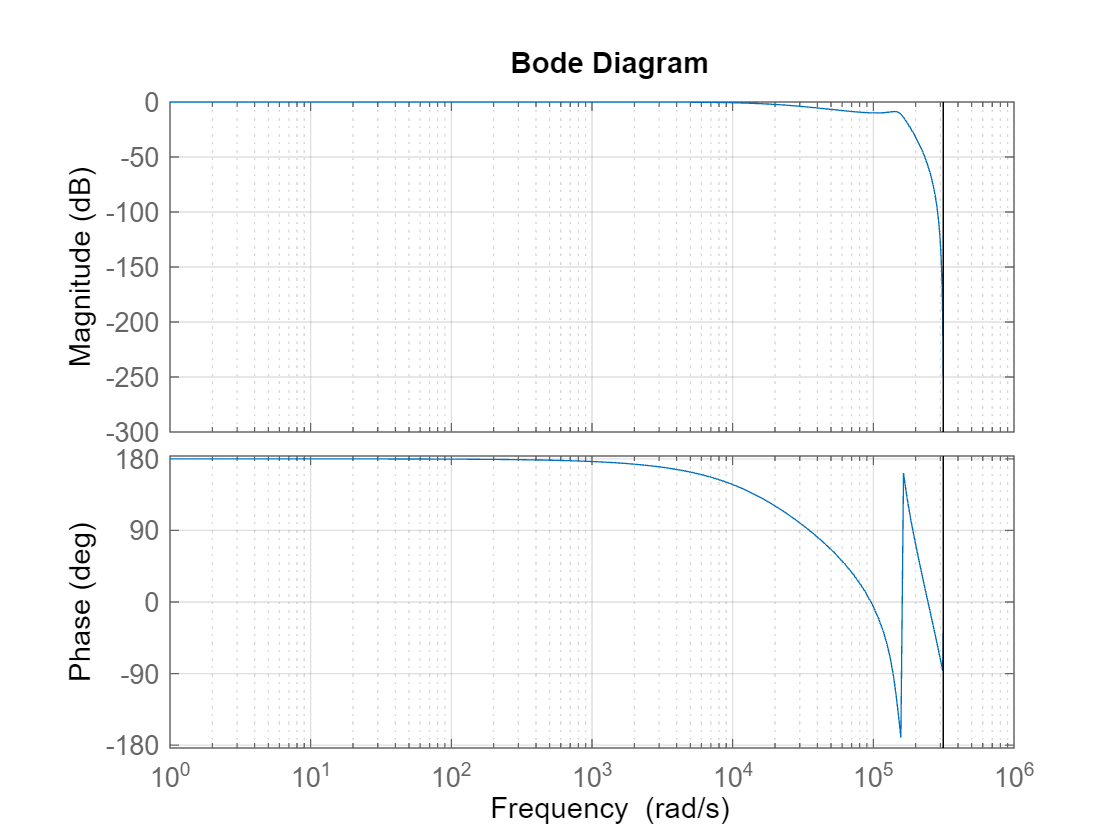

bode(G,{1,1e6})

This is a low pass filter.  That has nice properties for ILC learning!

Here I am adding a bit of realism by acknowledging that the system is uncertain.  The parameters are not particularly meaningful.

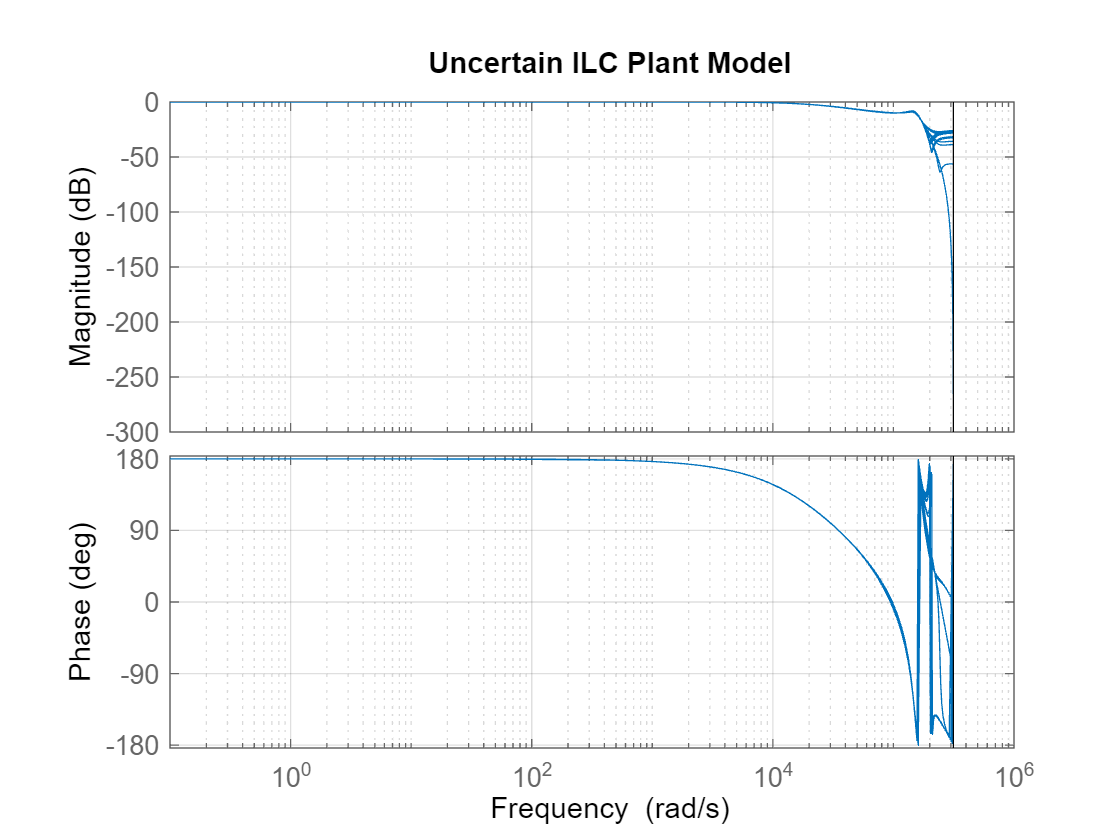

Delta = ultidyn('Delta',1);  %This requires the robust control toolbox
WA = 0.005*makeweight(0.01,3e4,10,Ts);  %In practice this would be fit to a set of gathered measured complementary sensitivity functions.
Gp = minreal(G)+WA*Delta;  %We will grab an "actual" plant from this set for testing.
Gact = usample(Gp);
bode(Gp)
title('Uncertain ILC Plant Model')

### Reference

We now need a reference that is worth tracking.  Let's look at a minimum jerk trajectory that links the points x0 and x1.  It is relatively easy to change this to a "real" trajectory.

Tref = Ts;  %Same as the plant sampling rate
tendMove = 0.001;  %Final time of the move
tendSim = 0.005;  %Final time of the simulation
x0 = 0;
x1 = 0.5;  %Change this for different trajectories - no need to change both this and the end time
tmove = [0:Tref:tendMove];

The below is the standard formulation for a minimum jerk move.

pre = 100;  %Number of samples of preview
r = x0+(x1-x0)*(10*(tmove/tendMove).^3-15*(tmove/tendMove).^4+6*(tmove/tendMove).^5);
r = [r(1)*ones(1,pre),r,r(end)*ones(1,ceil((tendSim-tendMove)/Tref))]';  %Padded reference

Below is the trajectory plot.

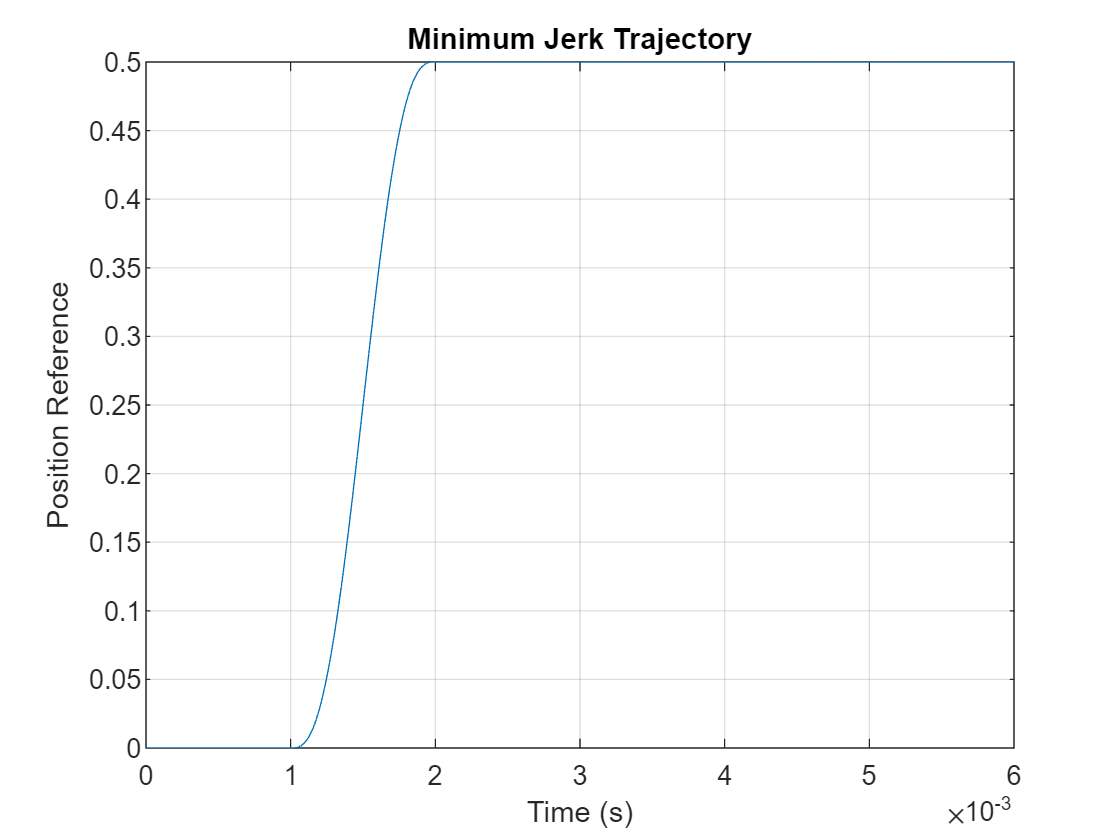

plot([0:Tref:tendSim+pre*Ts],r)
grid
title('Minimum Jerk Trajectory')
xlabel('Time (s)')
ylabel('Position Reference')

## Plant Inversion

Here we use the nominal plant model and find an approximate inverse.  The big problem that might occur is an unstable inverse.  I have avoided that in this example.  The secondary problem that *is* occurring that the inverse is improper.  

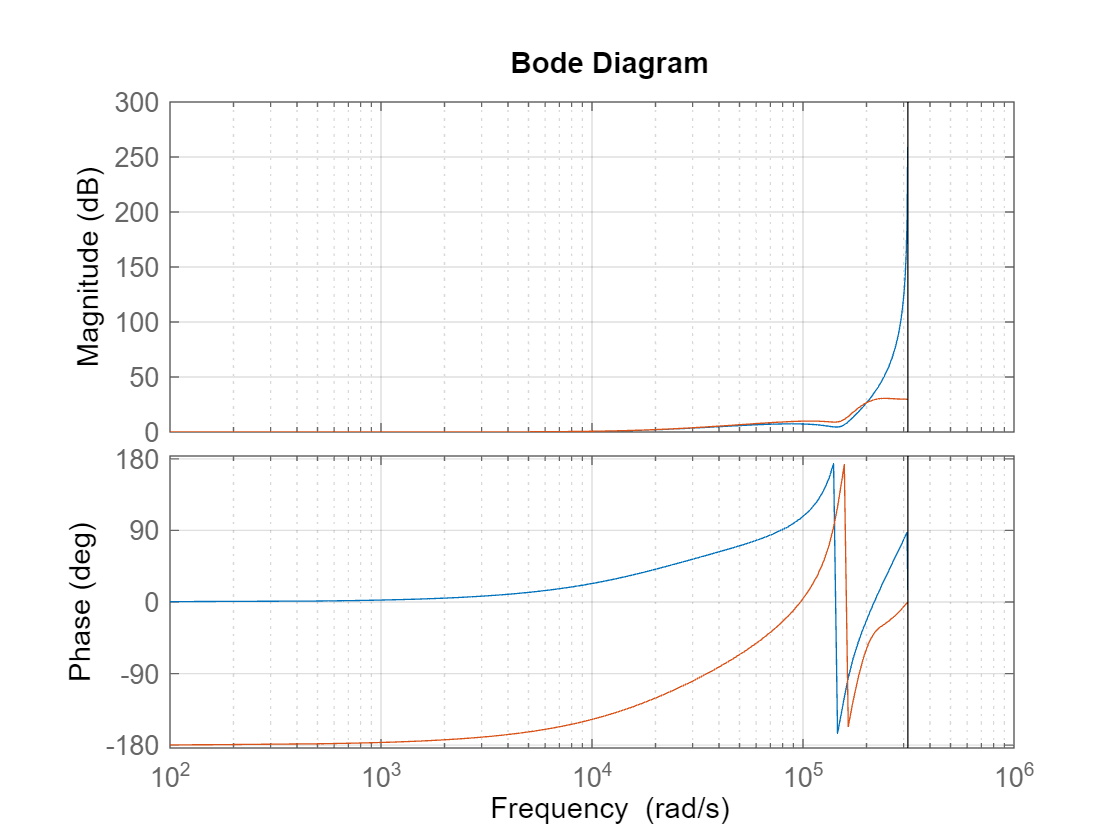

L = -tf(inv(G))*c2d(tf(1,[1/100000 1]),Ts,'matched');  %This term creates a proper model
bode(L,inv(Gact))

We now have a proper model, but the gain is VERY high at high frequency.  We will certainly need to do something about that.

[b,a] = butter(4,2e5/2/pi*2/Fs);
L = L*tf(b,a,Ts);
Gact = usample(Gp);

Now we have lost a bit of the match.  That will require the use of a $Q$ filter.

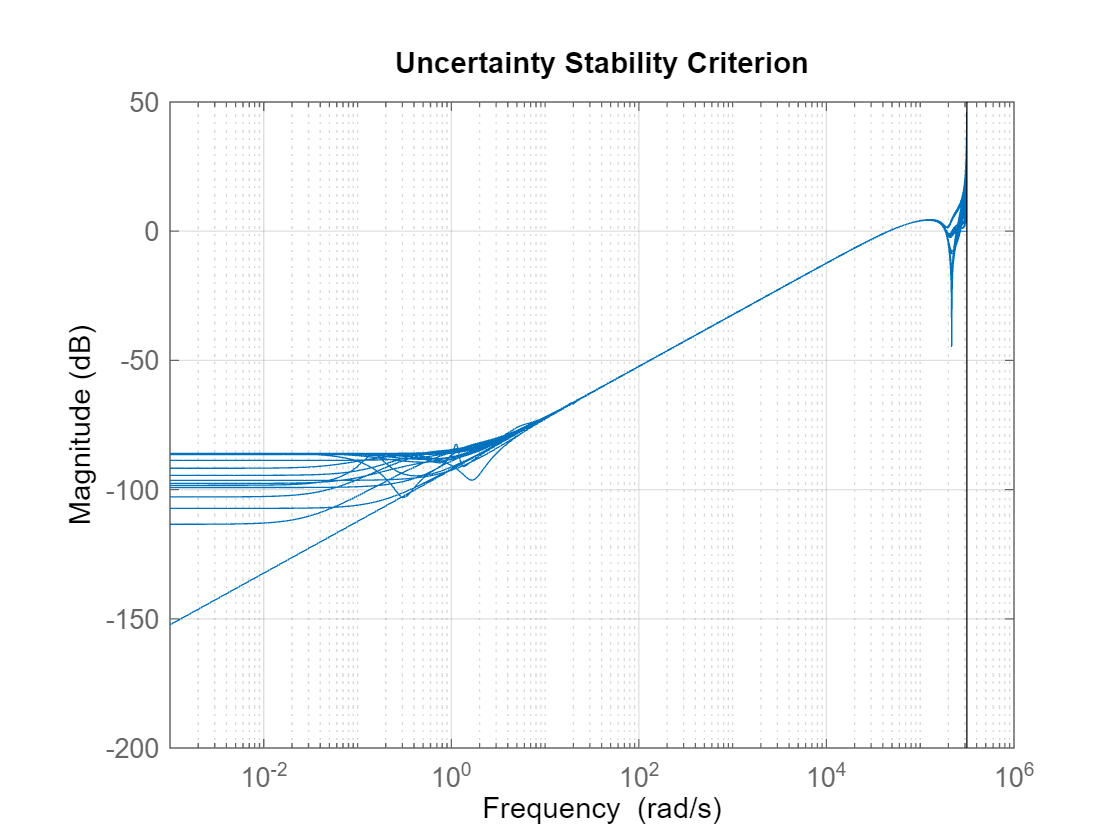

bodemag(1+L*Gp)
title('Uncertainty Stability Criterion')

It looks like we need a bit of high frequency filtering.

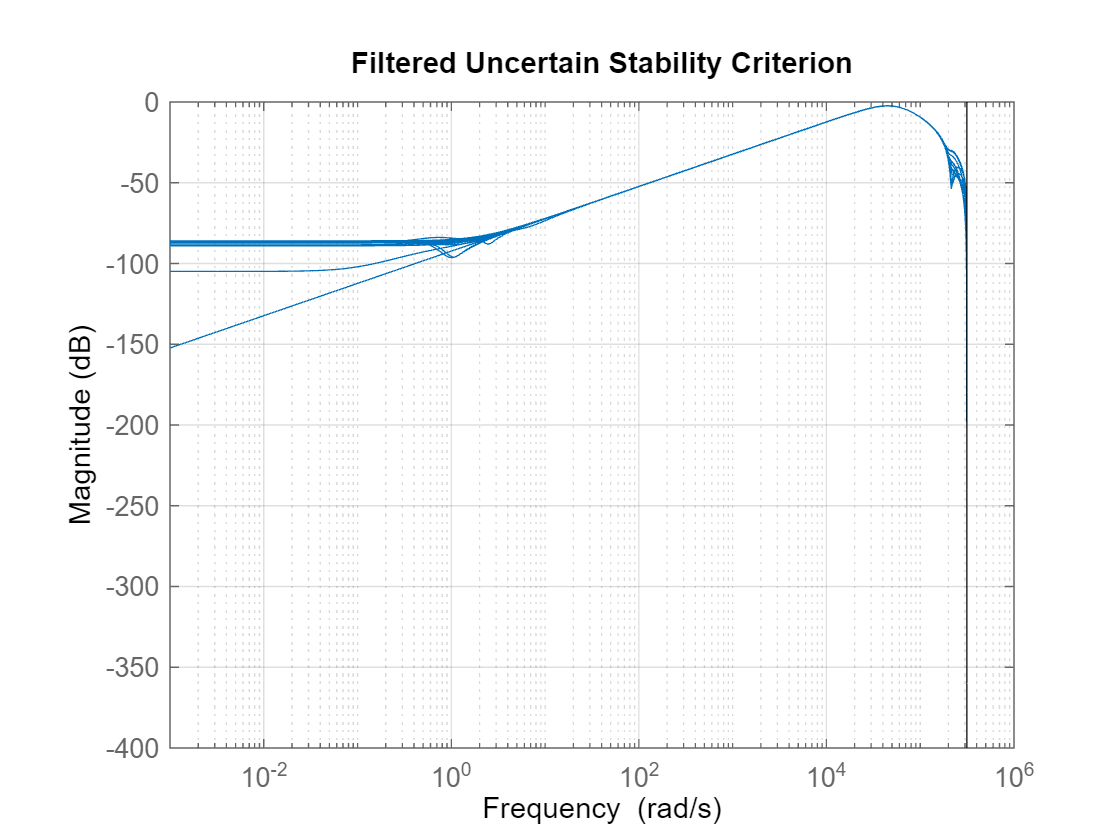

[bq,aq] = butter(2,5e4/2/pi*2/Fs);  %Arbitrarily chose a 2nd order Butterworth
Q = tf(bq,aq,Ts);
bodemag(Q*(1+L*Gp))
title('Filtered Uncertain Stability Criterion')

### Learning

The code below applies the learning, using lsim to simulate the LTI dynamics and the fact that the transfer function from $u$ to $y$ is $-G$.

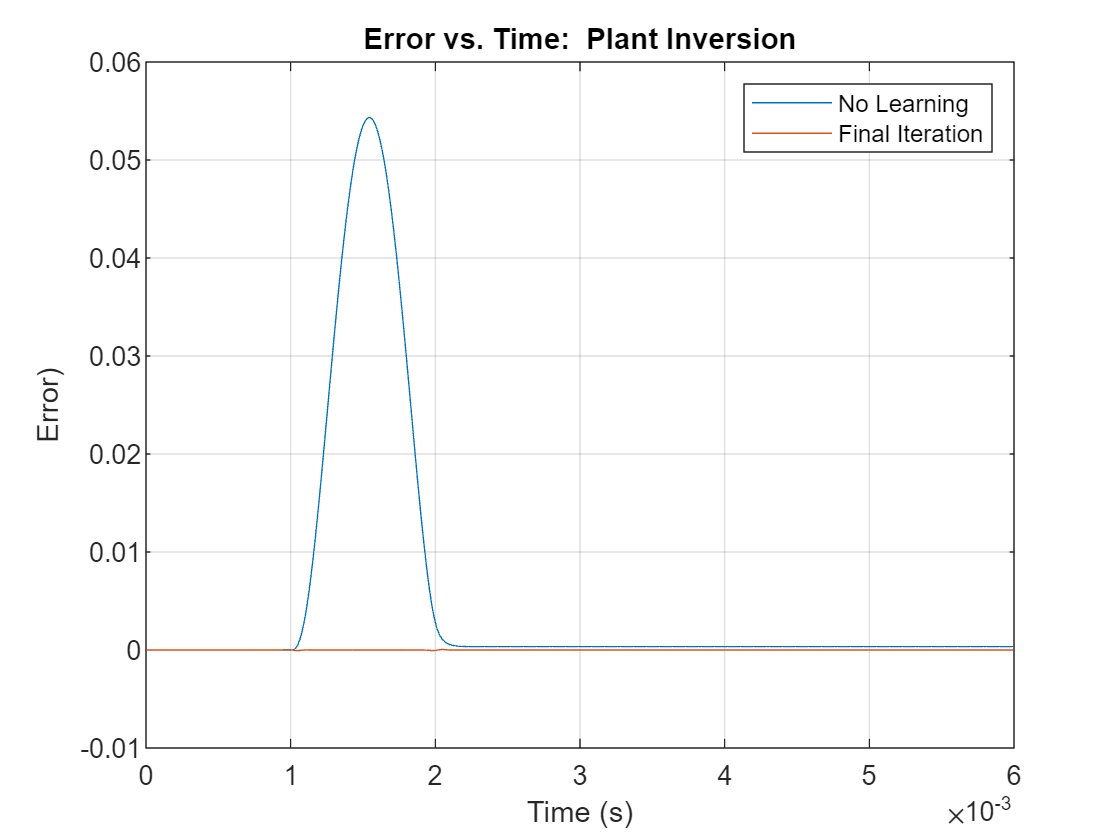

[bl,al] = tfdata(L,'v');
exInv = [];
enormInv = [];
uff = zeros(size(r));
Nit = 50;
for ii = 1:Nit
    exInv = [exInv,r-lsim(-Gact,uff+r)]; %-G is the complementary sensitivity function
    enormInv = [enormInv,norm(exInv(:,ii))];
    uff = filtfilt(bq,aq,uff+filter(bl,al,exInv(:,ii)));  %filtfilt gives Q zero phase
end
tvec = [0:Ts:Ts*(length(r)-1)];
plot(tvec,exInv(:,[1,end]))
title('Error vs. Time:  Plant Inversion')
legend('No Learning','Final Iteration');
grid
xlabel('Time (s)')
ylabel('Error)')

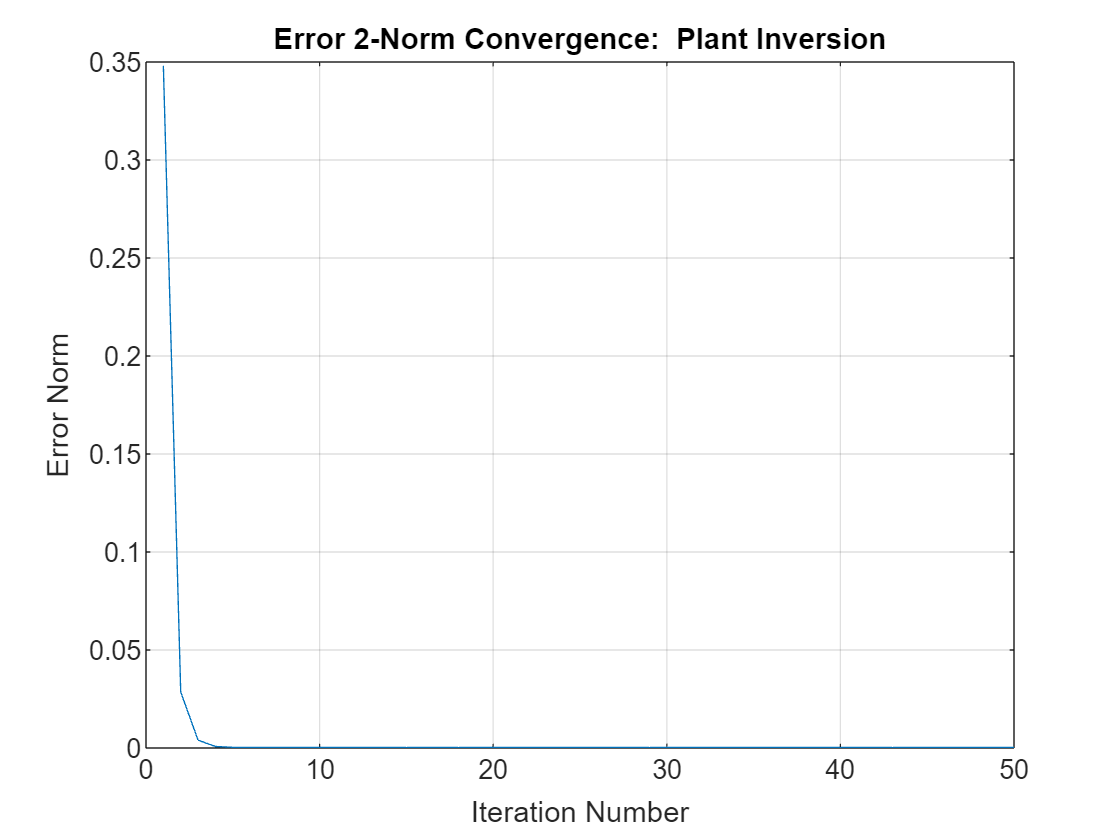

plot(enormInv)
title('Error 2-Norm Convergence:  Plant Inversion')
xlabel('Iteration Number')
ylabel('Error Norm')
grid

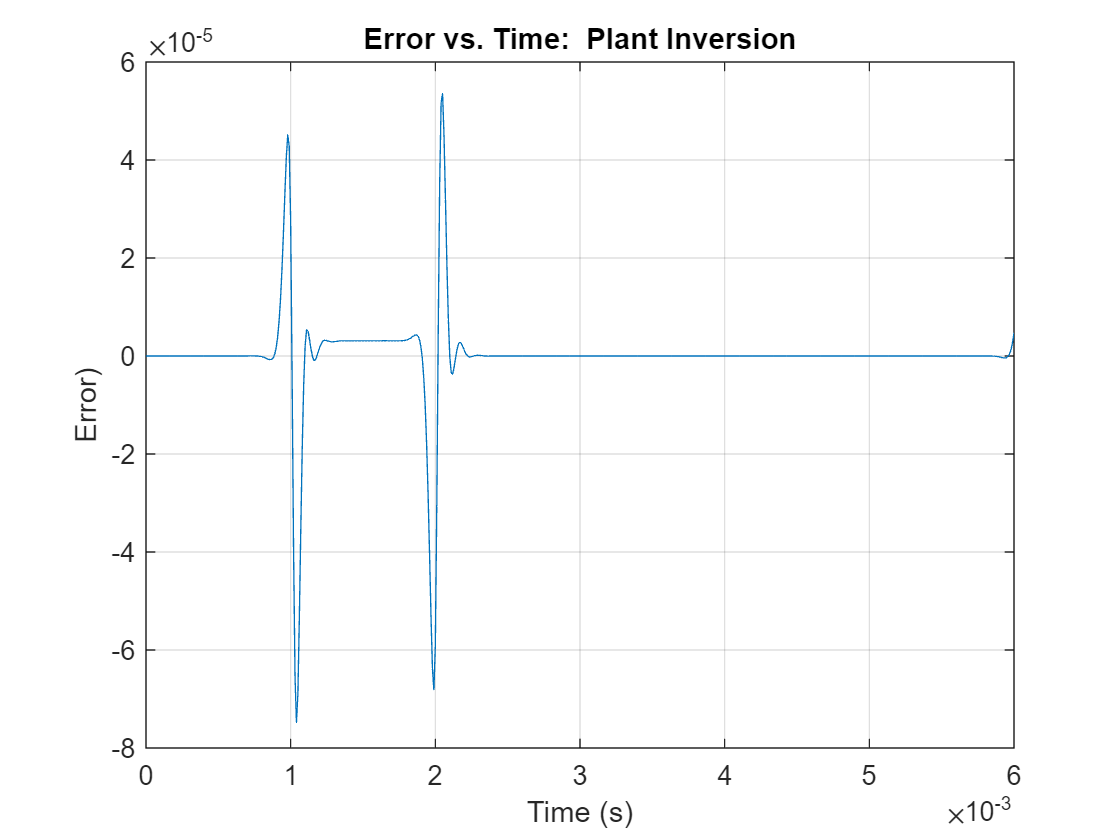

plot(tvec,exInv(:,[end]))
title('Error vs. Time:  Plant Inversion')
grid
xlabel('Time (s)')
ylabel('Error)')

## PD ILC

This is the classic approach described in the 2006 CSM "A Survey of Iterative Learning" paper (and many works before dating to the 80's).  We use an update law of the form $u_{j+1}(k) = Q(u_j(k)+K_P e_j(k)+K_D(e_j(k+1)-e_j(k)))$ with $Q$ a zero phase low pass filter to ensure stability and the gains chosen to get an approximate plant inverse (or tuned directly).  Note that this approach works particularly well given the block diagram above; the complementary sensitivity function is always basically a low pass filter with DC gain of 1; the PD controller is a high pass filter with a DC gain and bandwidth we get to choose.

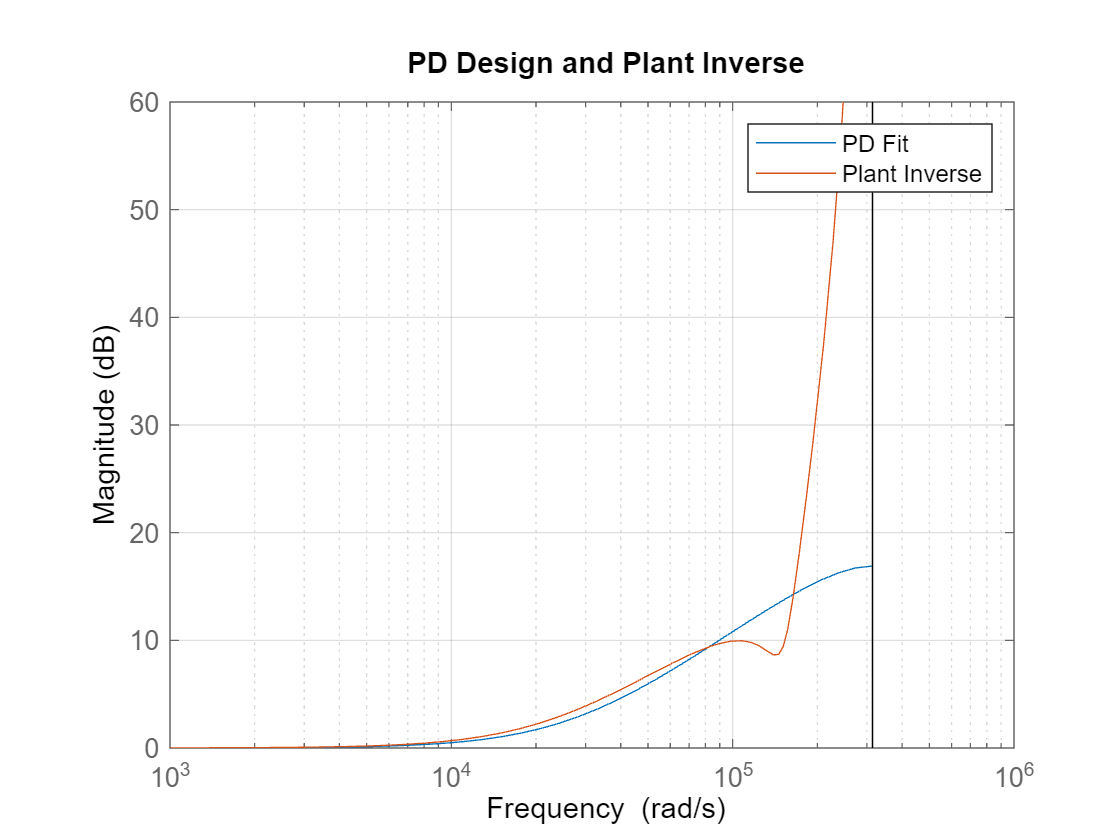

uff = zeros(length(r),1);
Kp = 1;  %The DC gain of the complementary sensitivity function is 1, so this is the inverse.
Kd = 3;  %I chose this to maximum the Q filter bandwidth
bodemag((Kp+(z-1)/z*Kd),1/G)
ylim([0,60])
legend('PD Fit','Plant Inverse')
title('PD Design and Plant Inverse')

For stability we need $\|1+LG\|_\infty<1$ - we can graphically check that to help design $Q$.

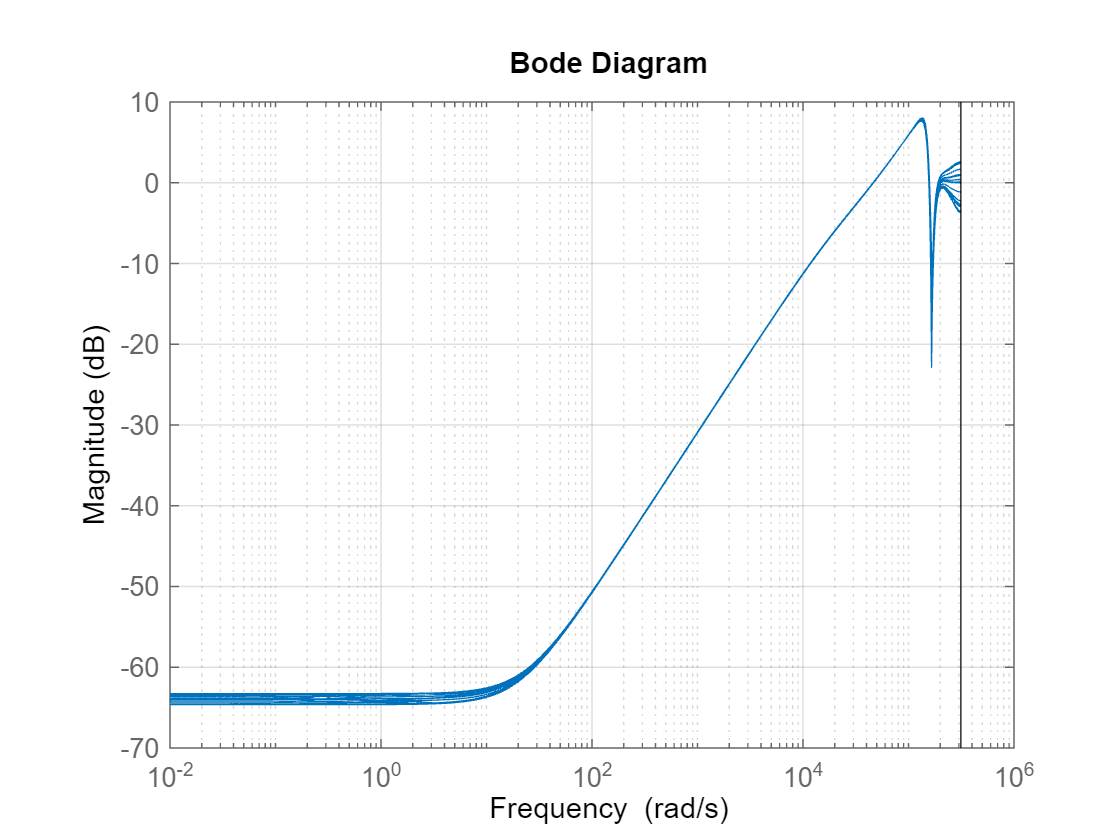

bodemag(1+(Kp+(z-1)/z*Kd)*Gp)

We need a touch of Q filtering.  Make the bandwidth high and check.  I iterated a bit on $Q$ below.  

[bq,aq] = butter(2,65000/2/pi*2/Fs);  %Arbitrarily chose a 2nd order Butterworth
Q = tf(bq,aq,Ts);
norm(Q*(1+(Kp+(z-1)/z*Kd)*G),'inf')  %Check stability - in principle we could maximize the bandwidth such that this is below 1.  I thought this was close enough given the uncertainty - we can see below that we are REALLY pushing it

ans = 0.9527

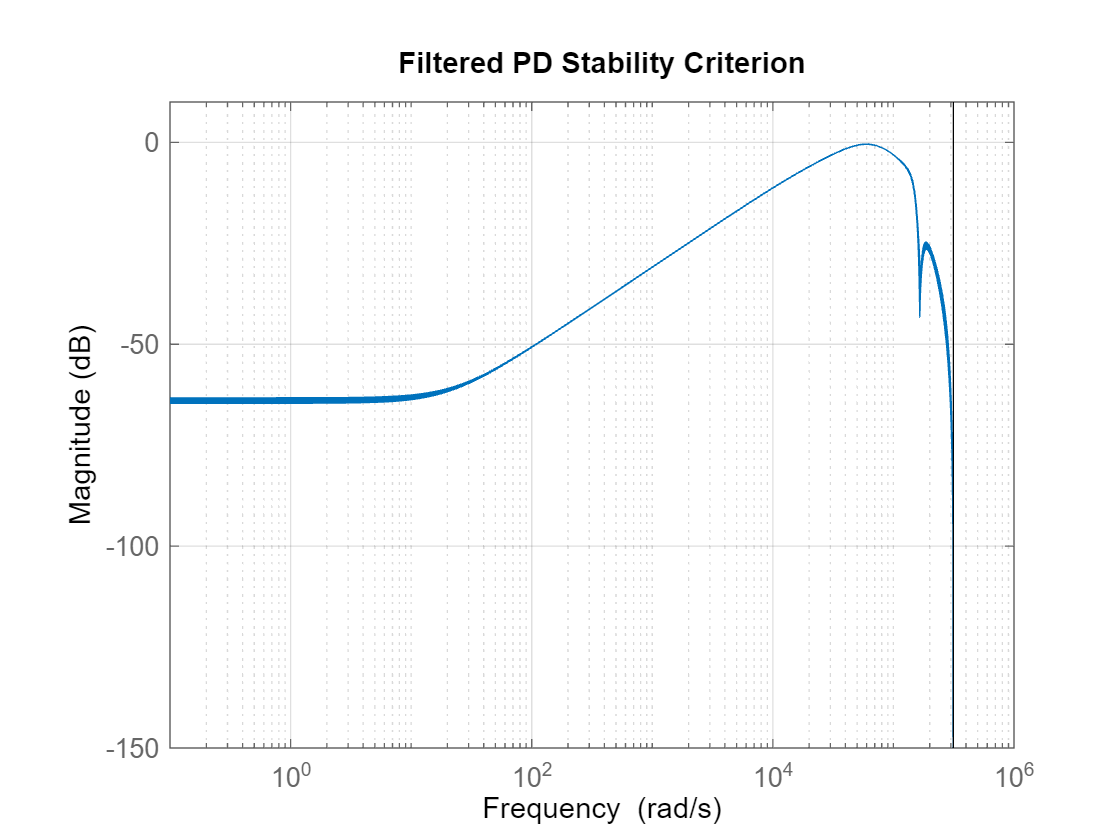

bodemag(Q*(1+(Kp+(z-1)/z*Kd)*Gp))
ylim([-150,10])
title('Filtered PD Stability Criterion')

1/robustperf(Q*(1+(Kp+(z-1)/z*Kd)*Gp)).LowerBound

ans = 0.9695

JUST made it!  Of course I tweaked the bandwidth above to make that true.  Everything above is trivial to put into Python except computing $\mu$. Frankly, we could do it based on the measurements and picking the maximum magnitude out of the measured set.

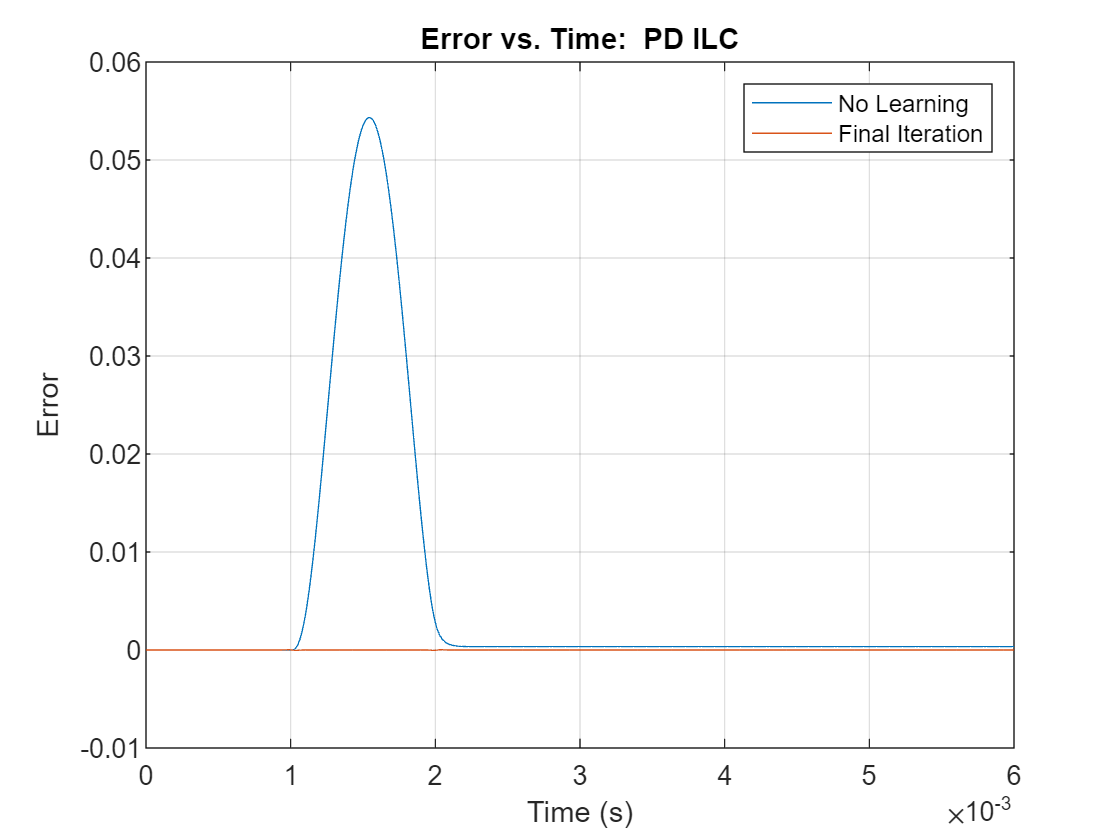

ex = [];
enorm = [];
for ii = 1:Nit
    ex = [ex,r-lsim(-Gact,uff+r)];
    enorm = [enorm,norm(ex(:,ii))];
    uff = filtfilt(bq,aq,uff+Kp*ex(:,ii)+Kd*[diff(ex(:,ii));0]);
end
plot(tvec,ex(:,[1,end]))
title('Error vs. Time:  PD ILC')
legend('No Learning','Final Iteration');
grid
xlabel('Time (s)')
ylabel('Error')

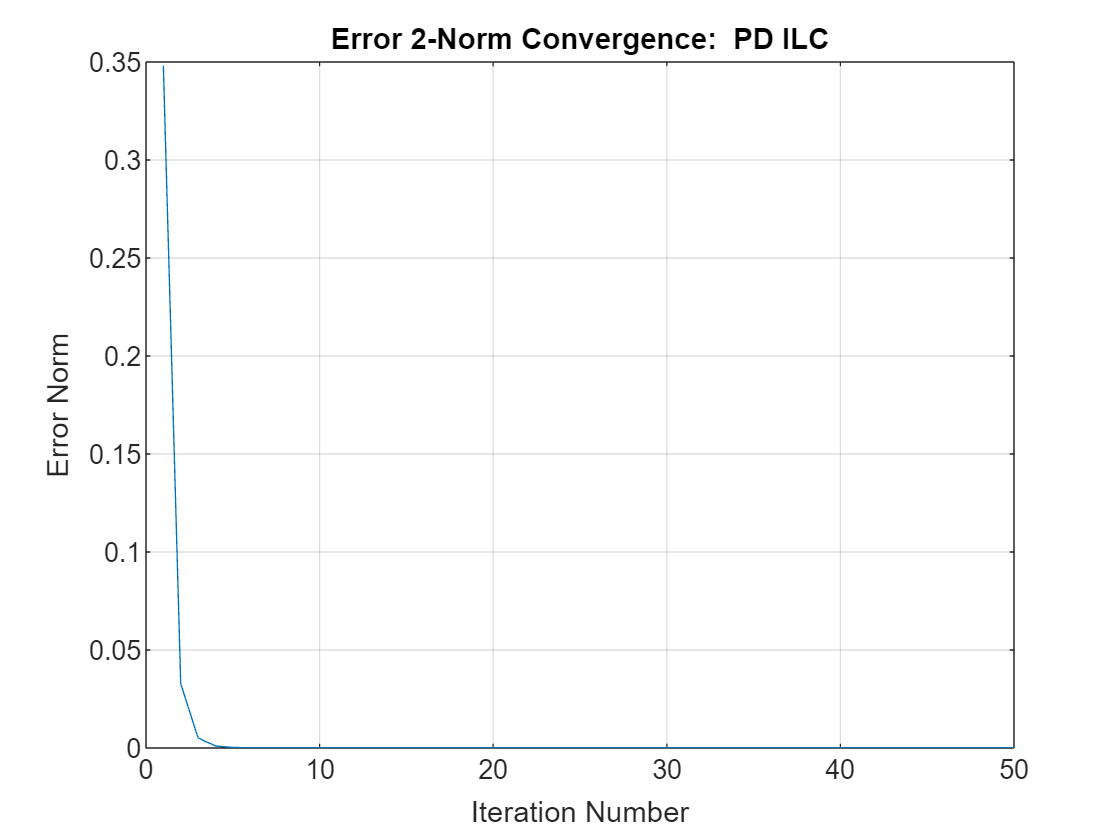

plot(enorm)
title('Error 2-Norm Convergence:  PD ILC')
grid
xlabel('Iteration Number')
ylabel('Error Norm')

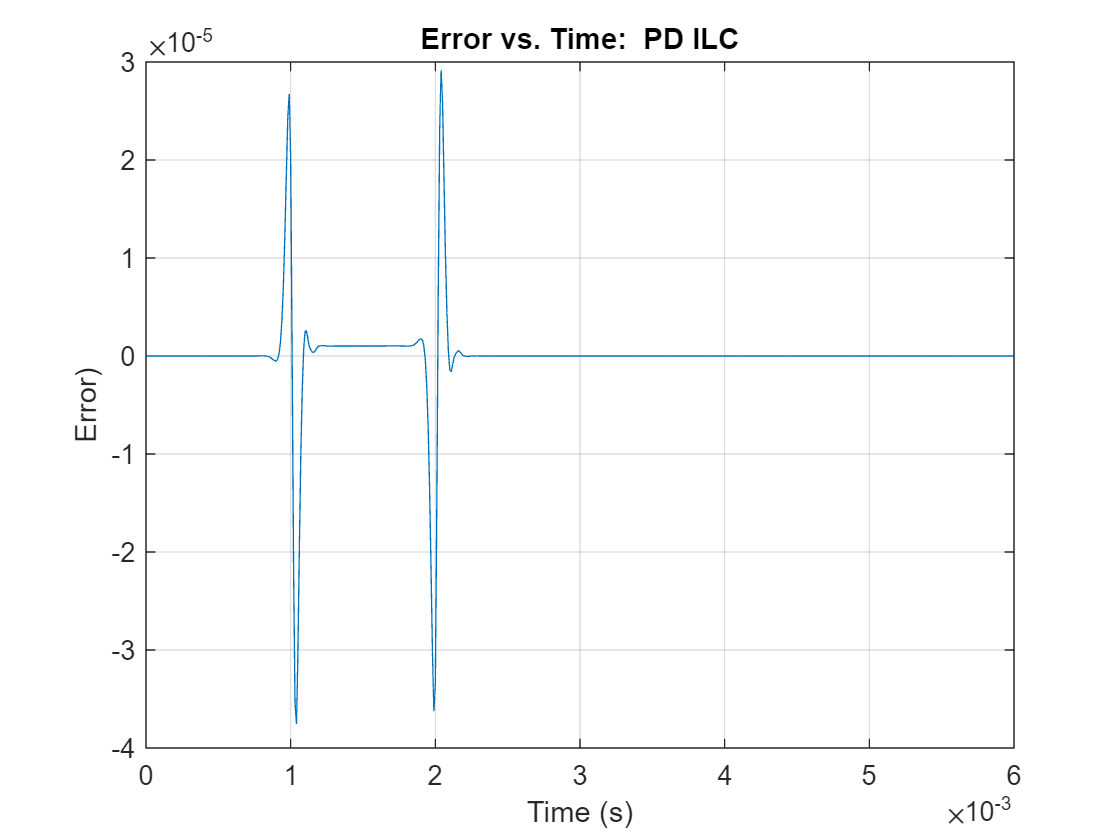

exILC = ex(:,end);
enormILC = enorm;
uStandard = uff;

plot(tvec,exILC)
title('Error vs. Time:  PD ILC')
grid
xlabel('Time (s)')
ylabel('Error)')

## $H_\infty$ Optimal Learning

$H_\infty$ is a natural framework for ILC given that the stability criterion is in terms of an $H_\infty$ norm AND the convergence rate is related to the same norm.  The basic approach is to fix a $Q$ filter design and then optimize the infinity norm.  The great thing about this approach is that we can actually guarantee ROBUST stability in the design process. 

Here I'll solve the $H_\infty$ control problem assuming a certain plant model.  I am also solving the more appropriate $\mu$ synthesis problem that manages uncertainty below.

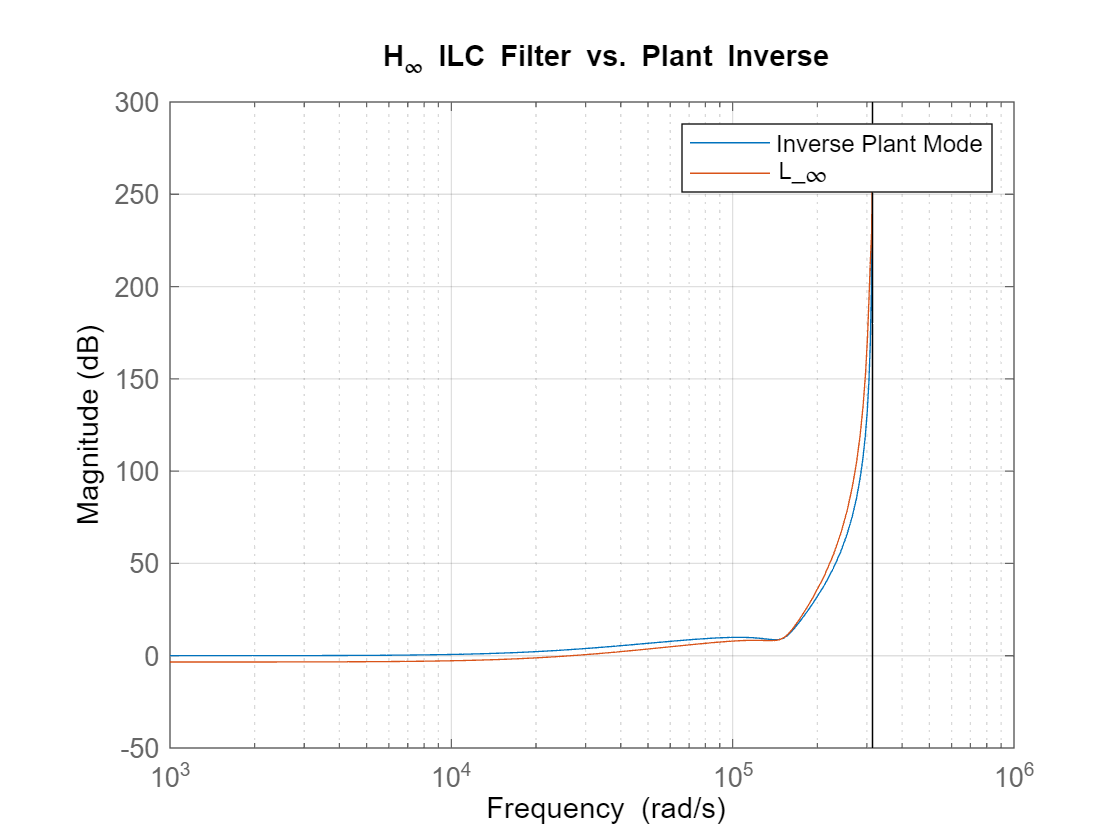

G = prescale(minreal(G));
% The choice of bandwidth directly trades off convergence speed with final error.
[num,den] = butter(2,25000*2/Fs);  %Can certainly play with this.  
Q = tf(num,den,Ts);
[b,a] = tfdata(Q,'v');
genPlant = [Q Q;G 0];  %This is for non-robust design.
[Kinf,~,gamma] = hinfsyn(prescale(genPlant),1,1);
bodemag(1/G,Kinf)
legend('Inverse Plant Mode','L_\infty')
title('H_\infty ILC Filter vs. Plant Inverse')

gamma

gamma = 0.3264

Is it robust?  Let's see whether it works with our plant sample.

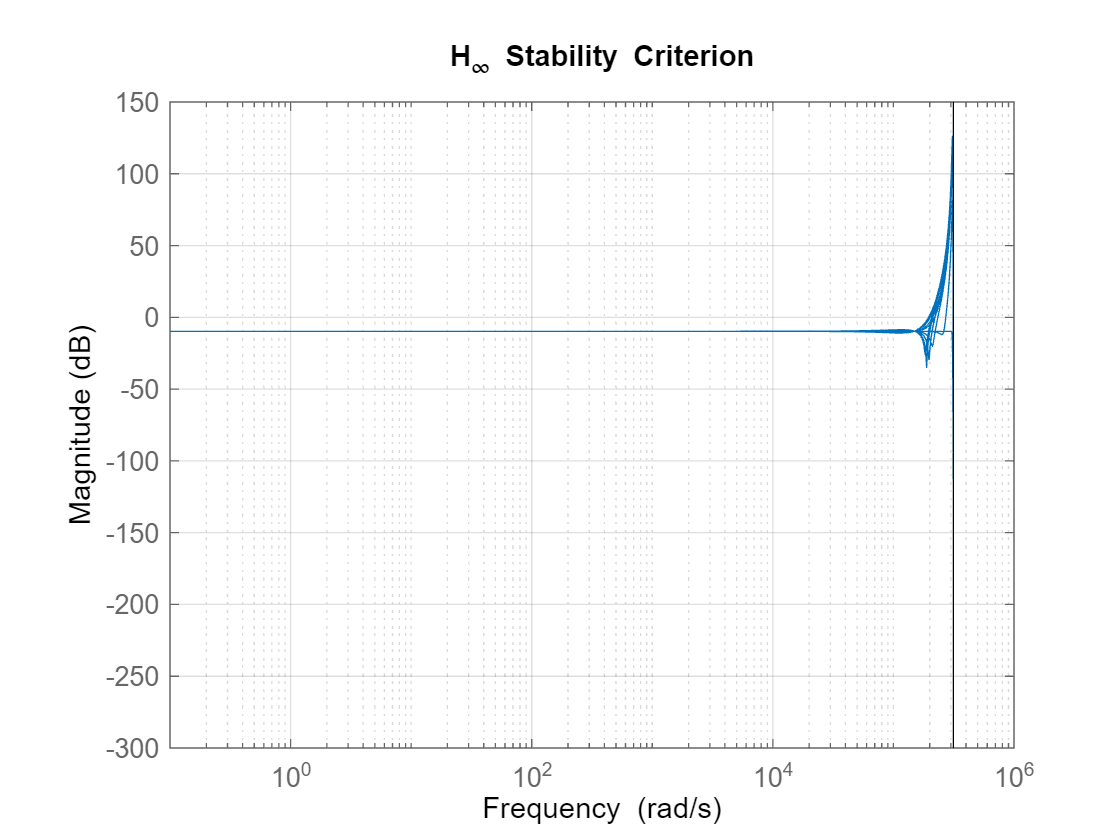

bodemag(Q*(1+Kinf*Gp))
title('H_\infty Stability Criterion')

The $H_\infty$ controller guarantees nominal convergence but will fail with the plant variations due to its aggression.  Let's check the robust solution.

Kmu = musyn([Q Q;Gp 0],1,1);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           1.283        1.279        12.31            10
    2           1.163        0.907       0.9159            10
    3          0.8815       0.8813       0.8815            10
    4          0.8714       0.8714        4.478            10
    5          0.8687       0.8686       0.9803             6
    6          0.8675       0.8675       0.9251             8

Best achieved robust performance: 0.867



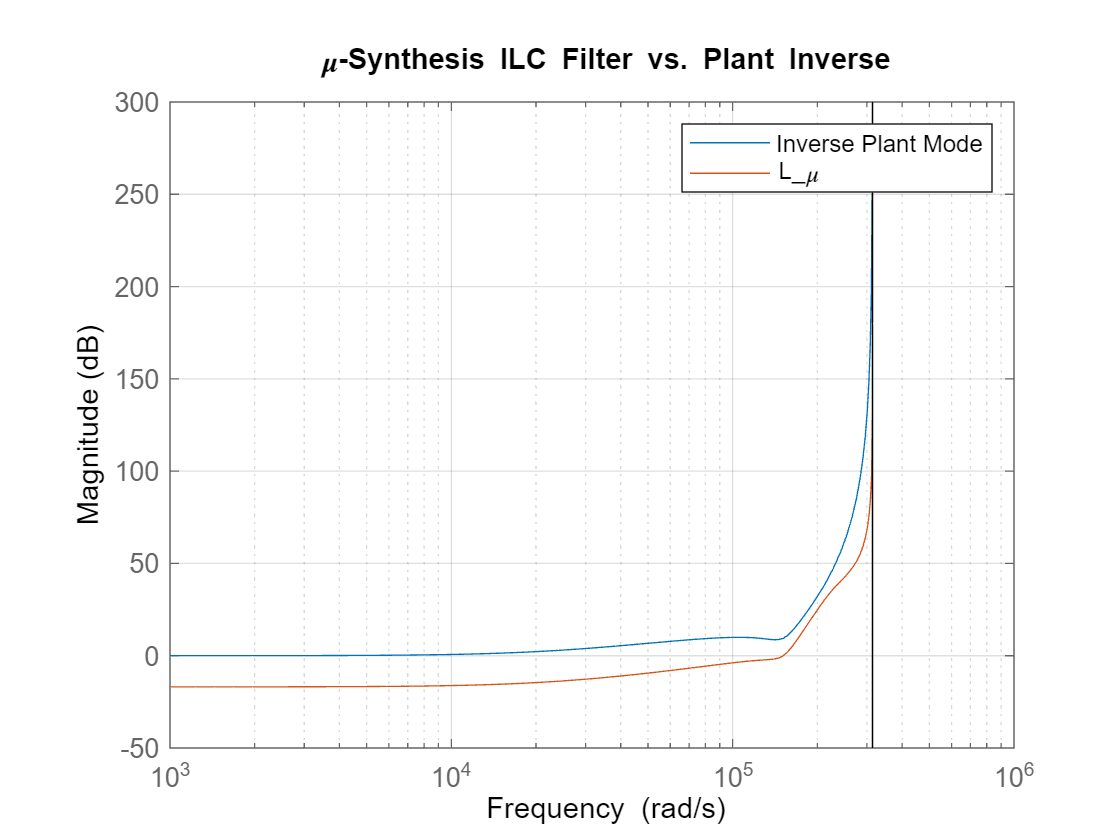

bodemag(1/G,Kmu)
legend('Inverse Plant Mode','L_\mu')
title('\mu-Synthesis ILC Filter vs. Plant Inverse')

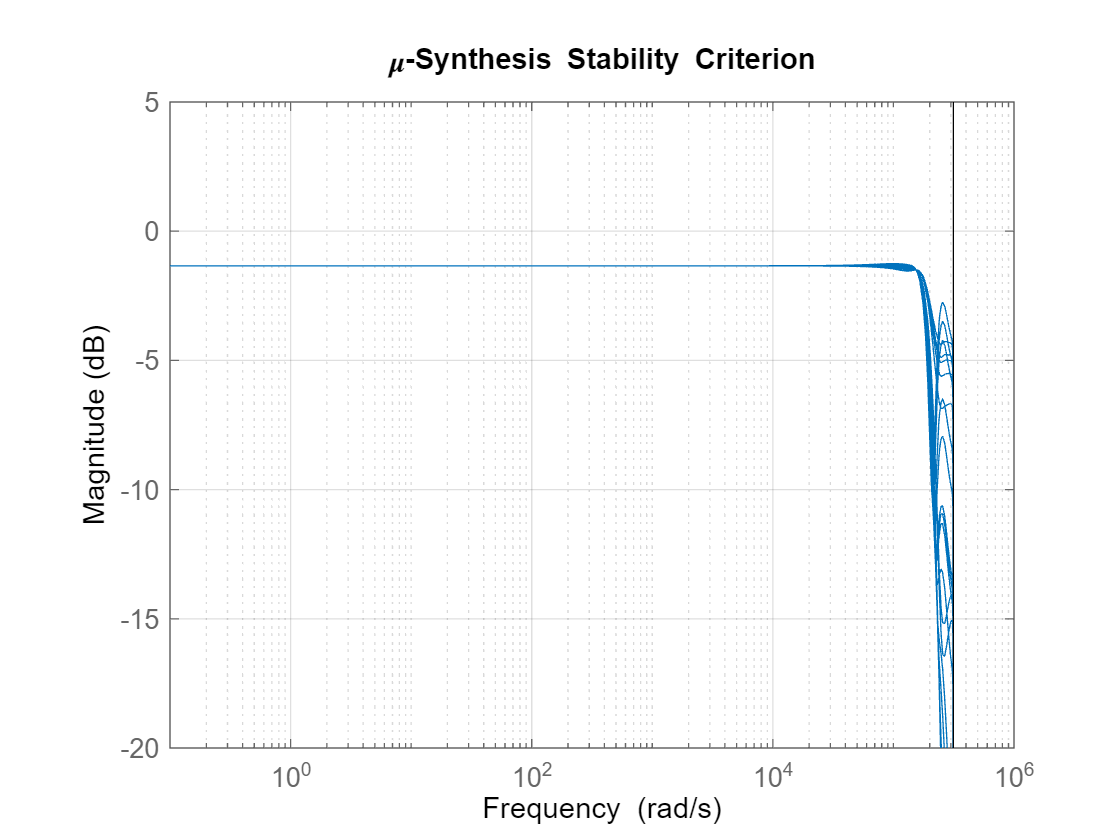

bodemag(Q*(1+Kmu*Gp))
ylim([-20,5])
title('\mu-Synthesis Stability Criterion')

Clearly the $\mu$ controller is RS as well and will converge more quickly.

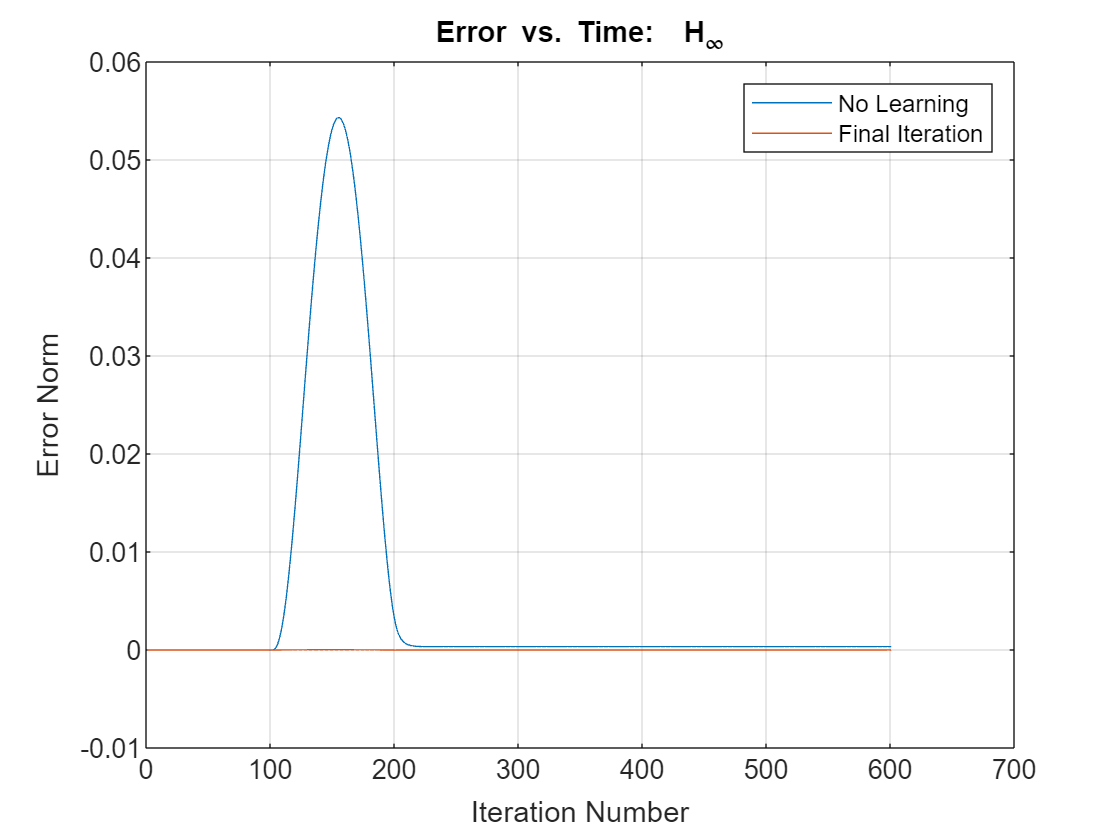

Kact = Kmu;  %To allow switching between H_\infty and \mu controllers if desired.  H_\infty is supported in Python, but \mu is not.
[bk,ak] = tfdata(Kact,'v');
ex = [];
enorm = [];
uff = zeros(length(r),1);
for ii = 1:Nit
    ex = [ex,r-lsim(-Gact,uff+r)];
    enorm = [enorm,norm(ex(:,ii))];
    Delta_Uff = filter(bk,ak,ex(:,ii));  %Apply the learning filter
    uff = filtfilt(b,a,uff+Delta_Uff);  %Apply the Q filter
end
plot(ex(:,[1,end]))
title('Error vs. Time:  H_\infty')
legend('No Learning','Final Iteration');
grid
xlabel('Iteration Number')
ylabel('Error Norm')

This blows up at high numbers due to the finite length effects in the reference.  To overcome those effects in practice we can append extra samples at the end of the reference and not use those controls.  

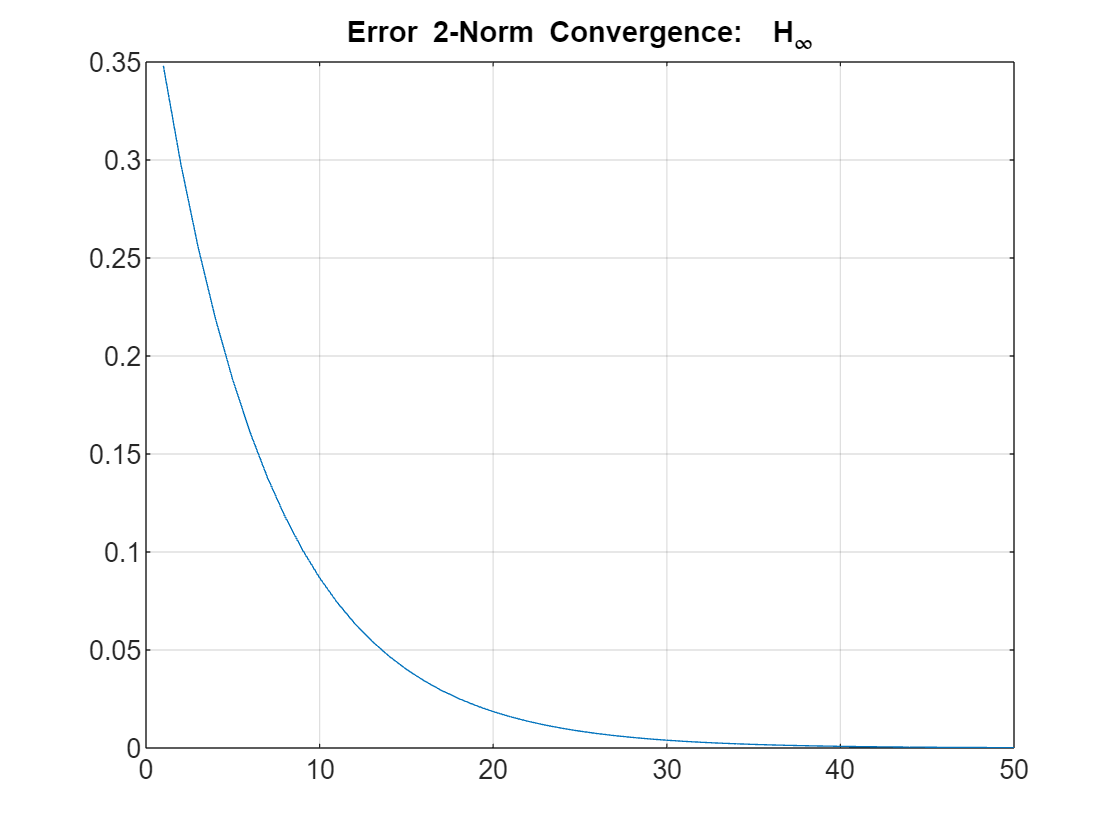

uInf = uff;
exInf = ex(:,end);
enormInf = enorm;
plot(enorm)
title('Error 2-Norm Convergence:  H_\infty')
grid

This is slow because it is cautiously guaranteeing robustness.  We can change the $Q$ filter bandwidth above (decrease it) to speed up the performance.

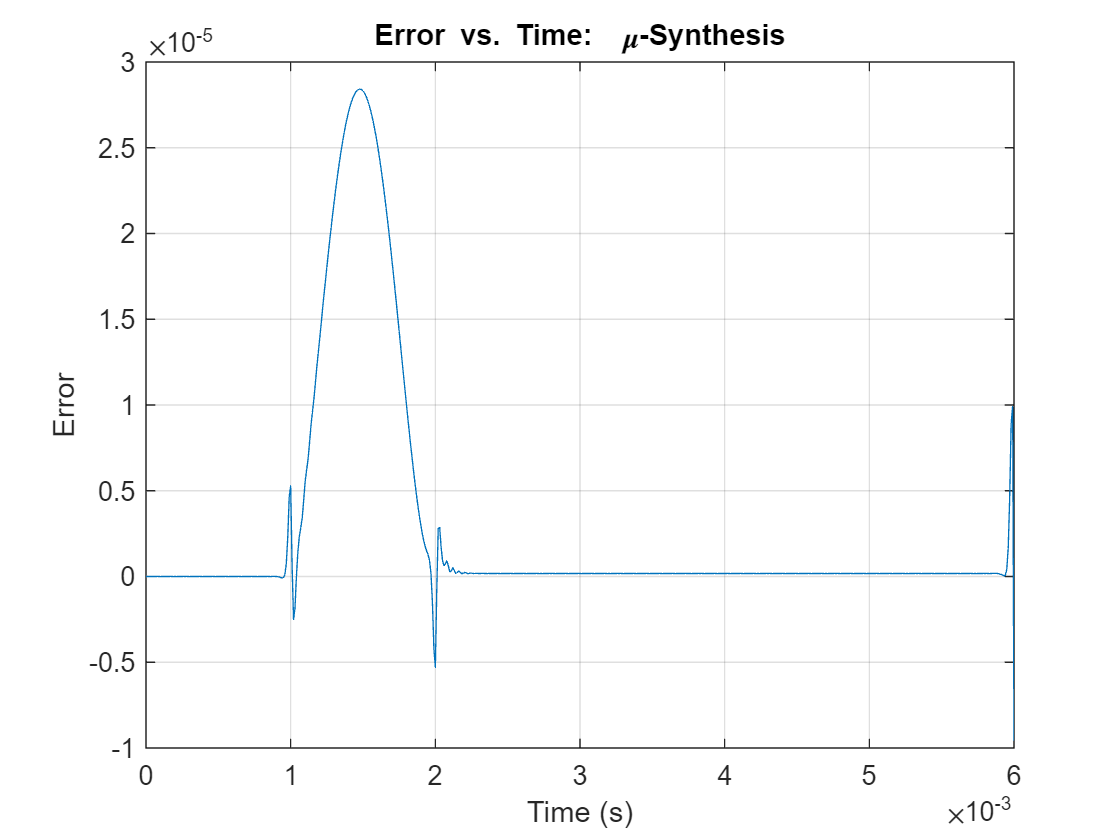

plot(tvec,ex(:,end))
title('Error vs. Time:  \mu-Synthesis')
xlabel('Time (s)')
ylabel('Error')
grid

## Data-Driven Approach to Inversion

To start with we will build a fake frequency response model we can use.

N = 1000;  %Number of points in the measurement
fmin = 10*2*pi;  %Starting frequency
fmax = 40000*2*pi;   %Stopping frequency
freqs = linspace(fmin,fmax,N);
[mag,phase] = bode(G,freqs);
resp = squeeze(mag.*exp(phase*pi/180*j));

Now we can attempt to reconstruct the impulse response from the data.  We will want an impulse response that matches the length of the reference for filtering.  That will require both interpolation of the measured data and extrapolation to frequencies that are not measured.  For extrapolation here I am just holding the first and last values.

L = ceil(length(r)/2);
Ftot = 2*pi*linspace(0,Fs/2,L);  %This is the vector we will compute responses over
respint = interp1(freqs,resp,Ftot(find(Ftot<fmax & Ftot>fmin)));  %Interpolate
respext = [respint(1)*ones(length(find(Ftot<=fmin)),1);respint';respint(end)*ones(length(find(Ftot>=fmax)),1)]';  %Extrapolate

Now compute the ifft.

ymeas = Fs*(ifft(ifftshift([fliplr(conj(respext(2:end))),respext]),'symmetric'));
dt = 1/Fs;
timpmeas = dt*(0:length(ymeas)-1)';
yimpmeas = ymeas;

Let's compare the impulse responses to see how well we did.

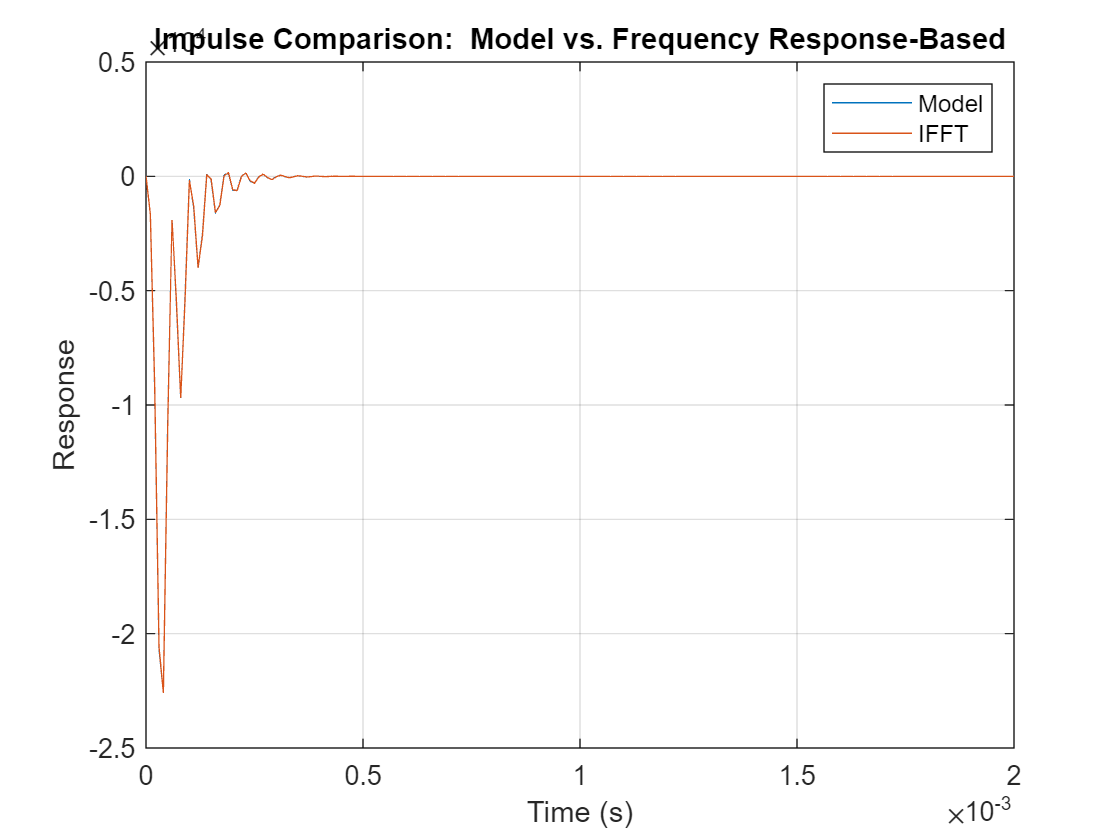

[ymod,tmod] = impulse(G,timpmeas(end));
plot(tmod,ymod,timpmeas,yimpmeas)
grid
title('Impulse Comparison:  Model vs. Frequency Response-Based')
xlim([0 2e-3])
legend('Model','IFFT')
xlabel('Time (s)')
ylabel('Response')

Now we need to build the impulse response into a filter.  This can get BIG!

Gbar = -tril(toeplitz(yimpmeas));

Now we will try to learn, using the same $Q$ filter as in the original plant inversion approach.

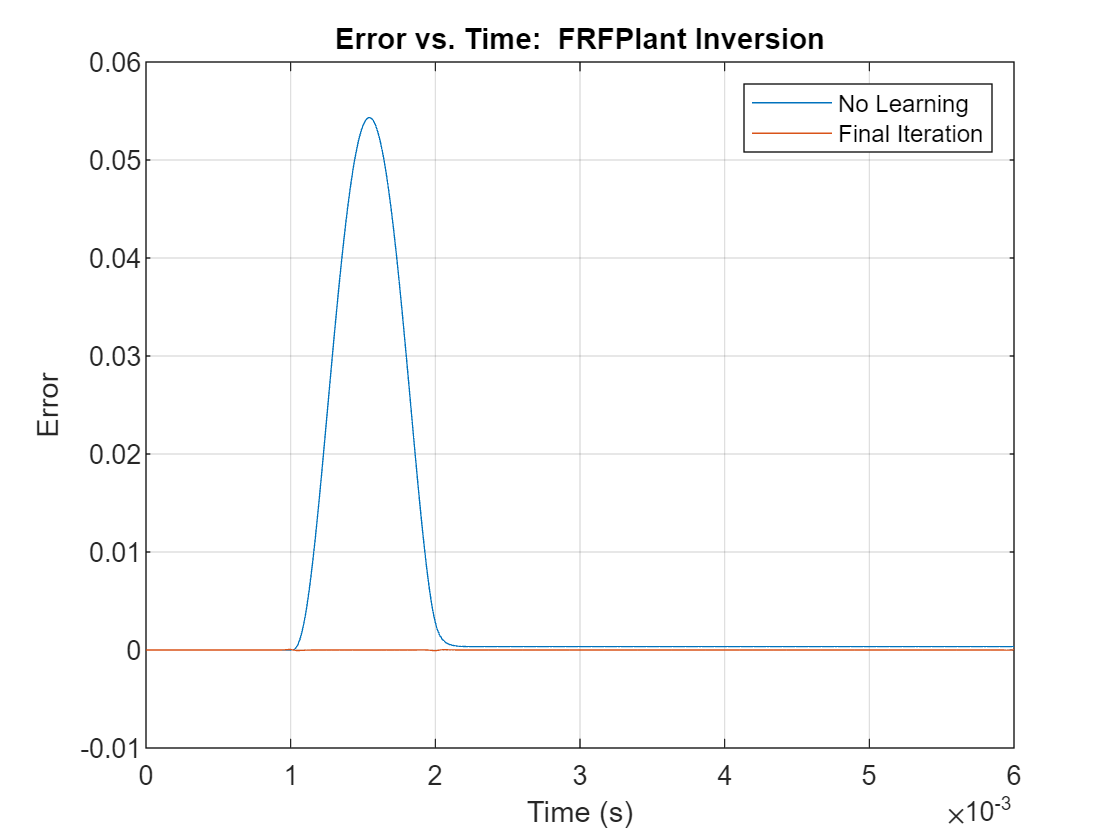

[bq,aq] = butter(2,5e4/2/pi*2/Fs);  %Arbitrarily chose a 2nd order Butterworth
exFRFInv = [];
enormFRFInv = [];
uff = zeros(size(r));
Nit = 50;
for ii = 1:Nit
    exFRFInv = [exFRFInv,r-lsim(-Gact,uff+r)]; %-G is the complementary sensitivity function
    enormFRFInv = [enormFRFInv,norm(exFRFInv(:,ii))];
    uff = filtfilt(bq,aq,uff+Fs*pinv(Gbar)*exFRFInv(:,ii));  %filtfilt gives Q zero phase
end
tvec = [0:Ts:Ts*(length(r)-1)];
plot(tvec,exFRFInv(:,[1,end]))
title('Error vs. Time:  FRFPlant Inversion')
legend('No Learning','Final Iteration');
grid
xlabel('Time (s)')
ylabel('Error')

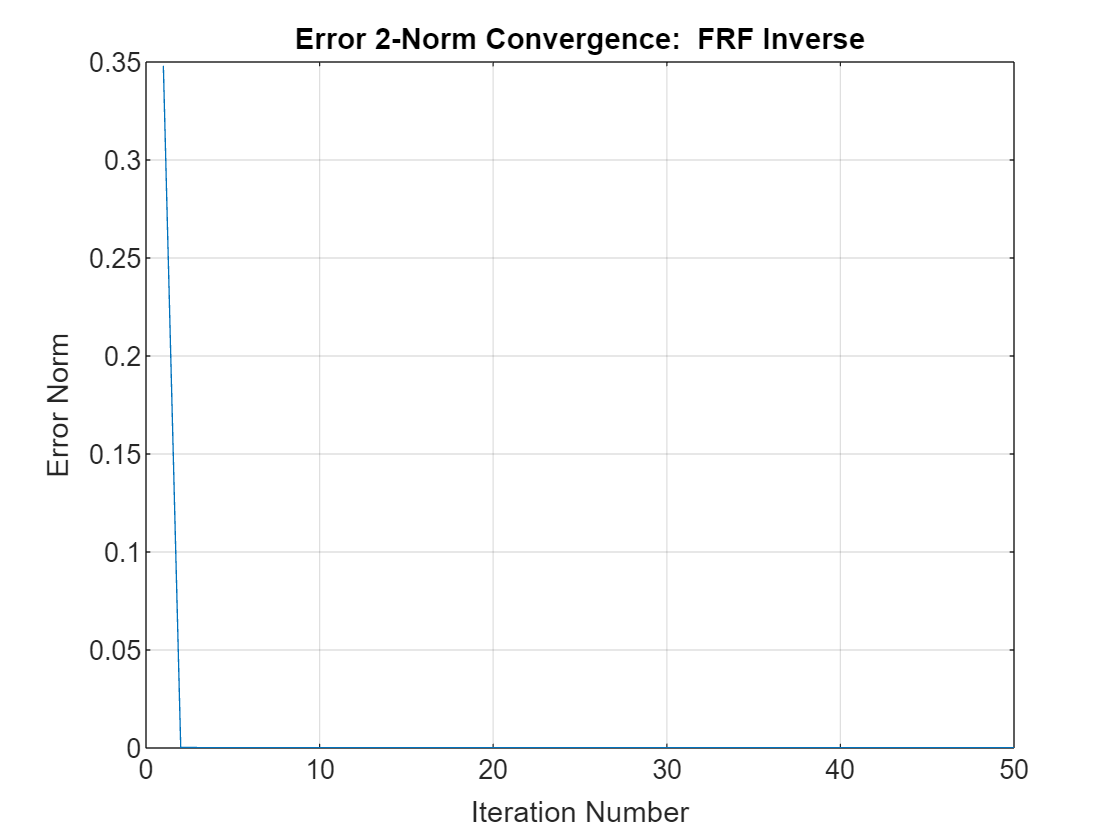

plot(enormFRFInv)
title('Error 2-Norm Convergence:  FRF Inverse')
grid
xlabel('Iteration Number')
ylabel('Error Norm')

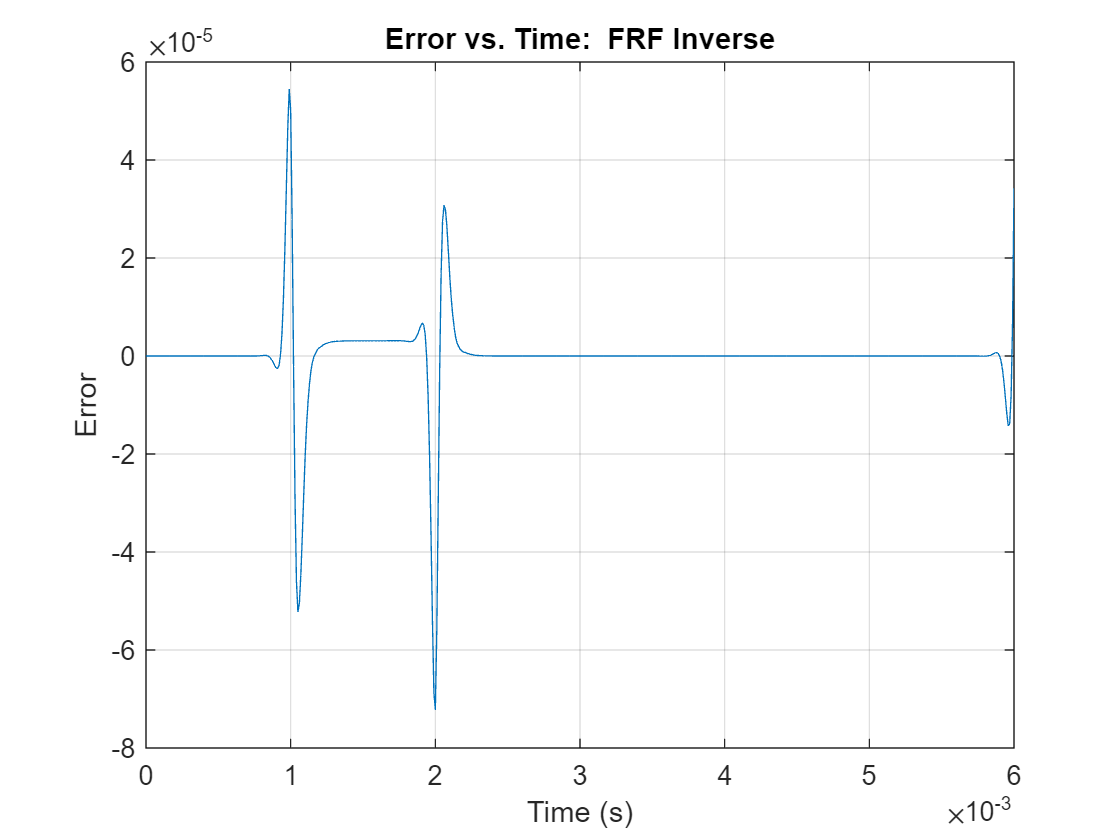

plot(tvec,exFRFInv(:,end))
title('Error vs. Time:  FRF Inverse')
xlabel('Time (s)')
ylabel('Error')
grid

## LQ ILC

This approach solves a LQ optimal control problem that minimizes the cost function $J = e_{j+1}^TW_ee_{j+1}+u_{ff_{j+1}}^TW_uu_{ff_{j+1}}+\left(u_{ff_{j+1}}-u_{ff_j}\right)^TW_\Delta\left(u_{ff_{j+1}}-u_{ff_j}\right)$ in lifted form.  There is no guarantee of convergence (unlike the $H_\infty$ solution above) but with weight tuning convergence should occur for large enough penalties on the control weights.  The solution is given in "Resource-Efficient ILC..." in 2016 IFAC Mechatronics.  

As this is LQ control we can start with a state space model.

[A,B,C,D] = ssdata(-G);  %Note that I am using the model from u to y to match the paper

Now we *can* make the weights be index-dependent, but I will keep them constant for now.  Note that for this problem convergence requires weighting on Wd.

We = 1;
Wf = 0;
Wdvec = [0.05:.5:2.05];
%Wdvec = [0.05];
enormVec = [];
for qq = 1:length(Wdvec)
    Wd = Wdvec(qq);

Define intermediate variables as in Theorem 6 of the paper.

gamma = inv((D'*We*D+Wf+Wd));
nx = size(A,1);
P = zeros(nx,nx,length(r));
gg = zeros(nx,1,length(r));
Kg = zeros(nx,1,length(r));
for ii = length(r)-1:-1:1
    P(:,:,ii) = (A'-C'*We*D*gamma*B')*P(:,:,ii+1)*(eye(nx)-B*inv(1/gamma+B'*P(:,:,ii+1)*B)*B'*P(:,:,ii+1))*(A-B*gamma*D'*We*C)+C'*We*C-C'*We*D*gamma*D'*We*C;
    Kg(:,:,ii) = (A'-C'*We*D*gamma*B')*P(:,:,ii+1)*inv(eye(nx)+B*gamma*B'*P(:,:,ii+1))*B*gamma;
end
uff = zeros(length(r),1);

Now perform the iterations.

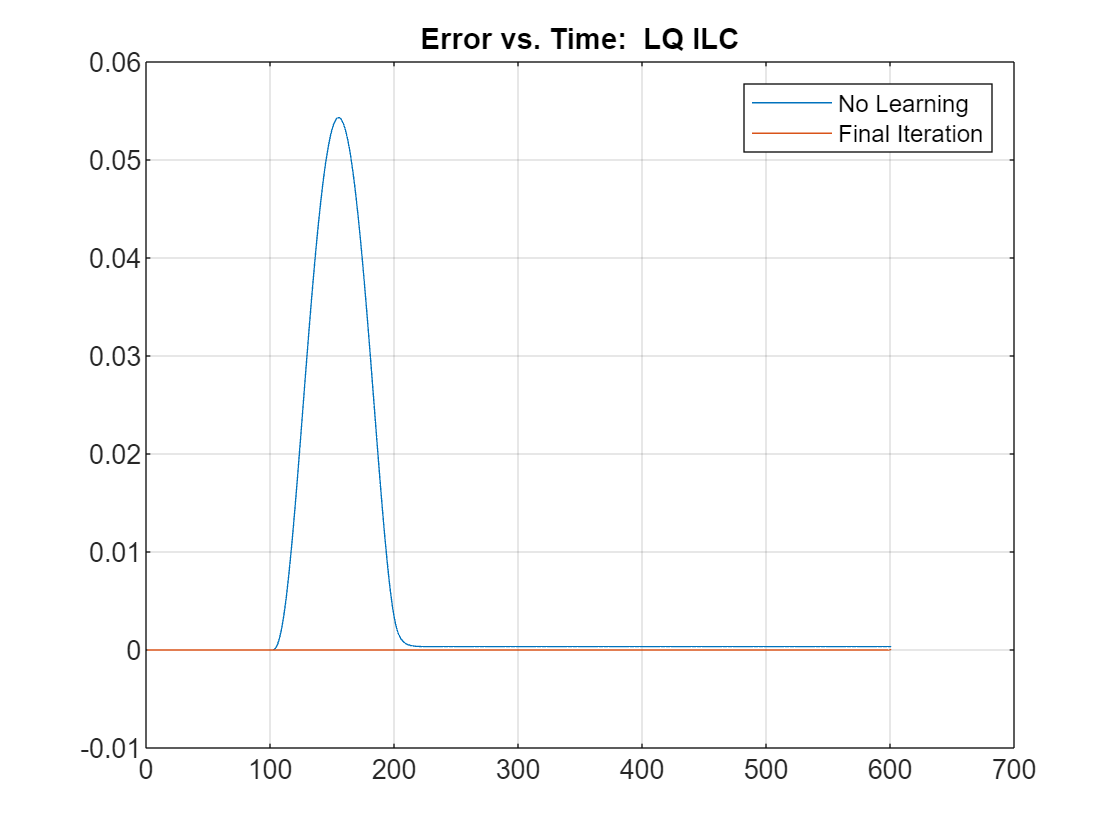

ex = [];
enorm = [];
for ii = 1:Nit
    %Compute the error
    ex = [ex,r-lsim(-Gact,uff+r)];
    enorm = [enorm,norm(ex(1:500,ii))];  %Truncate to avoid the end nonsense
    %Now the heavy lift in updating the controller
    for jj = length(r)-1:-1:1
       gg(:,:,jj) = (A'-Kg(:,:,jj)*B')*gg(:,:,jj+1)+C'*We*ex(jj,ii)+Kg(:,:,jj)*Wf*uff(jj);
    end
    %Finally, compute the next control
    x = zeros(size(A,1),1);
    for jj = 1:length(r)-1
        Lk = inv(1/gamma+B'*P(:,:,jj+1)*B)*(D'*We*C+B'*P(:,:,jj+1)*A);
        Lf = inv(1/gamma+B'*P(:,:,jj+1)*B)*Wf;
        Le = inv(1/gamma+B'*P(:,:,jj+1)*B)*D'*We;
        Lg = inv(1/gamma+B'*P(:,:,jj+1)*B)*B';
        x = (A-B*Lk)*x-B*Lf*uff(jj)+B*Le*ex(jj,ii)+B*Lg*gg(:,:,jj+1);
        uff(jj) = -Lk*x+(1-Lf)*uff(jj)+Le*ex(jj,ii)+Lg*gg(:,:,jj+1);
    end
end
enormVec = [enormVec enorm'];
end
plot(ex(:,[1,end]))
title('Error vs. Time:  LQ ILC')
legend('No Learning','Final Iteration');
grid

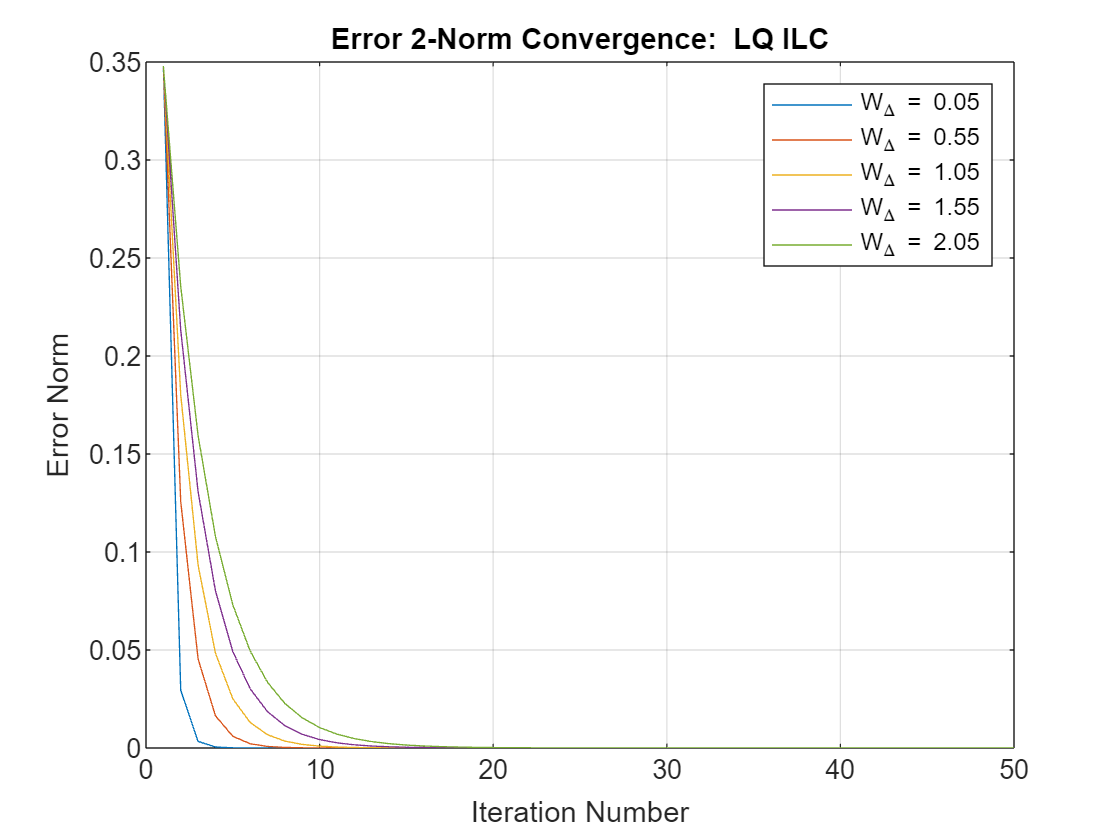

plot(enormVec)
title('Error 2-Norm Convergence:  LQ ILC')
grid
xlabel('Iteration Number')
ylabel('Error Norm')
legend('W_\Delta = 0.05','W_\Delta = 0.55','W_\Delta = 1.05','W_\Delta = 1.55','W_\Delta = 2.05')

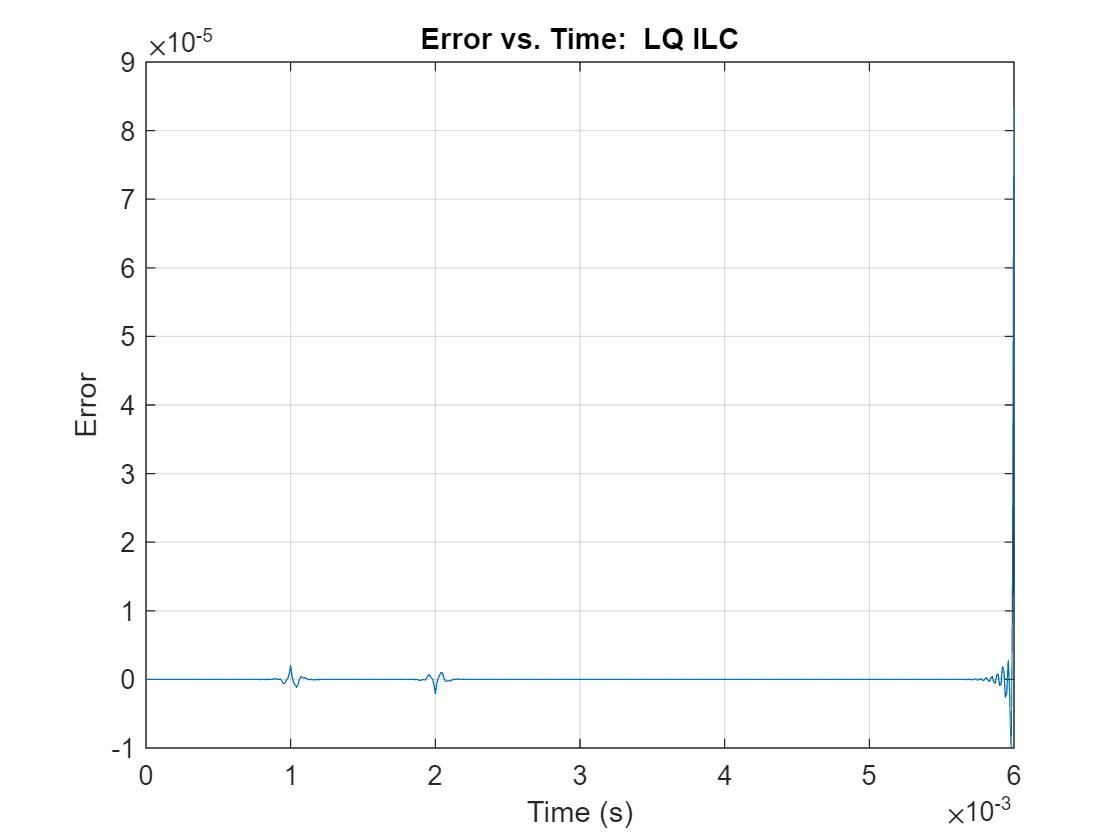

uLQ = uff;
exLQ = ex(:,end);
enormLQ = enorm;
plot(tvec,exLQ)
title('Error vs. Time:  LQ ILC')
xlabel('Time (s)')
ylabel('Error')
grid

## Filter Learning Approach

In this approach we attempt to actually fit a function to the plant inverse using an expansion that is linear in the unknown (learned) parameters.  This is quite different from the ILC approaches that attempt to learn a sequence of controls, especially in that it is highly transferrable to new references.  However, as we will see, it does not perform as well as ILC to a specific reference due to errors in the fitting process (limited basis set).

### Create Impulse Response Based on "Measured" FRF

Here we will use the IFFT to create an approximation to the complementary sensitivity impulse response.  We take the measured FRF and interpolate / extrapolate to find a set that we can effectively use the IFFT on.  This procedure matches nicely with taking the impulse of the known model.

L = ceil(length(r)/2);
Ftot = 2*pi*linspace(0,Fs/2,L);  %This is the vector we will compute responses over
respint = interp1(freqs,resp,Ftot(find(Ftot<fmax & Ftot>fmin)));  %Interpolate
respext = [respint(1)*ones(length(find(Ftot<=fmin)),1);respint';respint(end)*ones(length(find(Ftot>=fmax)),1)]';  %Extrapolate

Now compute the ifft.

ymeas = Fs*(ifft(ifftshift([fliplr(conj(respext(2:end))),respext]),'symmetric'));
dt = 1/Fs;
timpmeas = dt*(0:length(ymeas)-1)';
yimpmeas = ymeas;
Gbar = -tril(toeplitz(yimpmeas));  %This is a storage nightmare if the reference is large.  This is one big reason that this approach does not extend well to the general ILC problem. 
ex = [];
enorm = [];
theta = [];

Set the initial controller.

filterOrderVec = [2,5:5:20];
enormVec = [];
for qq = 1:length(filterOrderVec);
    theta = [];
    filterOrder = filterOrderVec(qq);  %This is the order of the Laguerre filter
    tinit = zeros(filterOrder,1);
    theta(:,1) = tinit;
    alpha_L = 0.5;  %The location of the Laguerre poles.  It is somewhat sensitive to this.
    rin = r;  %Change of variable names for convenience - meaningless
    psi = [];
    phi = [];
    for ii  = 1:filterOrder
        Laguerreii = zpk(1/alpha_L*ones(ii-1,1),alpha_L*ones(ii,1),sqrt(1-alpha_L^2),Ts);  %These are the Laguerre filters (1st order orthonormal basis)
        [num,den] = tfdata(Laguerreii,'v');
        psi = [psi;filter(num,den,rin)'];
        phi = [phi zpk(1/alpha_L*ones(ii-1,1),alpha_L*ones(ii,1),sqrt(1-alpha_L^2),Ts)];
    end
    psi = psi';  

### Perform Learning

    ex = [];
    enorm = [];
    Gact = usample(Gp,1);  %Grab an actual plant model (different from model used for learning) - the same sample is used for all versions below for a fair comparison
    for ii = 1:Nit
        ex = [ex,r-lsim(-Gact,psi*theta(:,ii)+r)];  %Run the simulation on the "actual" plant
        enorm = [enorm,norm(ex(:,ii))];
        theta(:,ii+1) = theta(:,ii)+Fs*pinv(Gbar*psi)*ex(:,ii);  %Update the parameter vector.
    end
    enormVec = [enormVec enorm'];
end

### Visualize Results

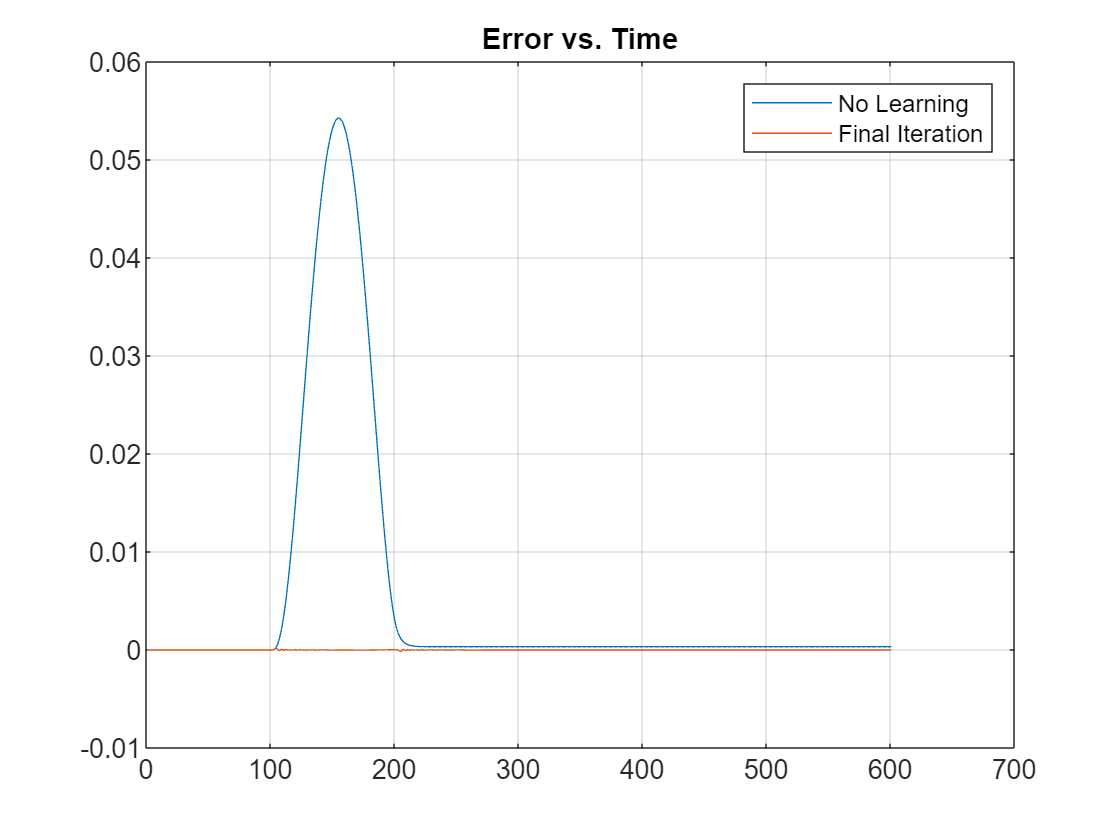

plot(ex(:,[1,end]))
title('Error vs. Time')
legend('No Learning','Final Iteration');
grid

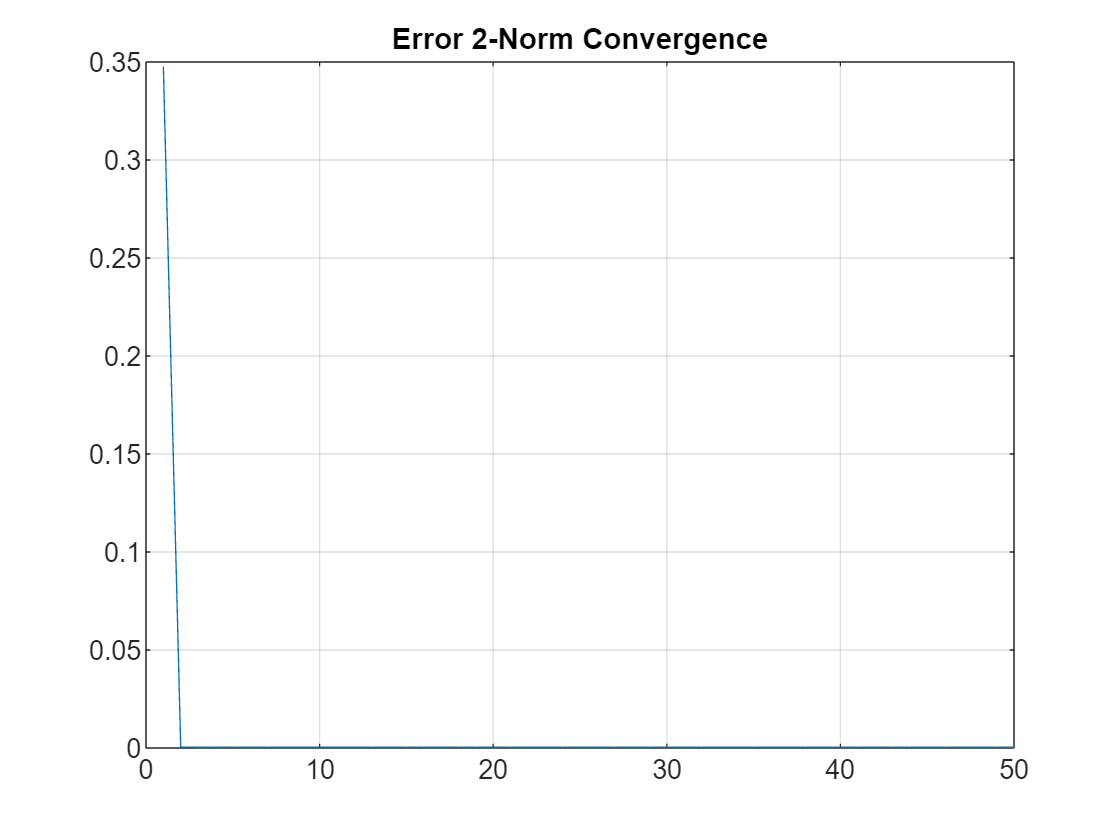

plot(enorm)
title('Error 2-Norm Convergence')
grid

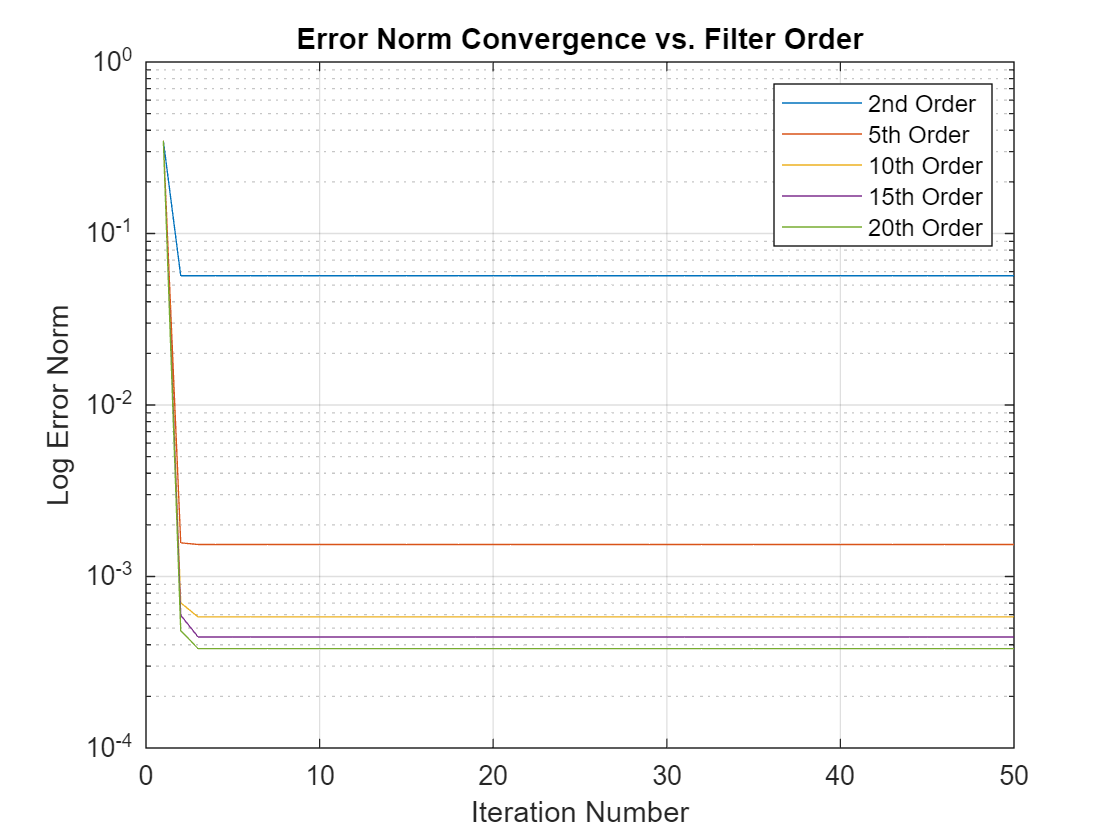

exLaguerre = ex(:,end);
enormLaguerre = enorm;
uLaguerre = psi*theta(:,end);

semilogy(enormVec)
grid
title('Error Norm Convergence vs. Filter Order')
xlabel('Iteration Number')
ylabel('Log Error Norm')
legend('2nd Order','5th Order','10th Order','15th Order','20th Order')

The procedure basically works, and convergence is very fast.  Using the same filters, we could get "decent" performance in tracking another reference.  This would be my preferred approach for generating the $C_{FF}$ in the block diagram, or it alteratively can be used to seed the ILC learning algorithms.

Now let's show that transferrability by tracking a different minimum jerk trajectory.

Tref = Ts;  %Same as the plant sampling rate
tendMove = 0.003;  %Final time of the move
tendSim = 0.005;  %Final time of the simulation
x0 = 0;
x1 = 1;  %Change this for different trajectories - no need to change both this and the end time
tmove = [0:Tref:tendMove];

The below is the standard formulation for a minimum jerk move.

pre = 100;  %Number of samples of preview
r2 = x0+(x1-x0)*(10*(tmove/tendMove).^3-15*(tmove/tendMove).^4+6*(tmove/tendMove).^5);
r2 = [r2(1)*ones(1,pre),r2,r2(end)*ones(1,ceil((tendSim-tendMove)/Tref))]';  %Padded reference
alpha_L = 0.5;  %The location of the Laguerre poles.  It is somewhat sensitive to this.
rin = r2;  %Change of variable names for convenience (don't have to change copy and pasted code) - meaningless
psi = [];
phi = [];
for ii  = 1:filterOrder
    Laguerreii = zpk(1/alpha_L*ones(ii-1,1),alpha_L*ones(ii,1),sqrt(1-alpha_L^2),Ts);  %These are the Laguerre filters (1st order orthonormal basis)
    [num,den] = tfdata(Laguerreii,'v');
    psi = [psi;filter(num,den,rin)'];
end
psi = psi';  

Now compute the response to the new reference with and without the filter applied.

e_nofilt = r2-lsim(-Gact,r2);
e_filt = r2-lsim(-Gact,psi*theta(:,ii)+r2);

Let's visualize.

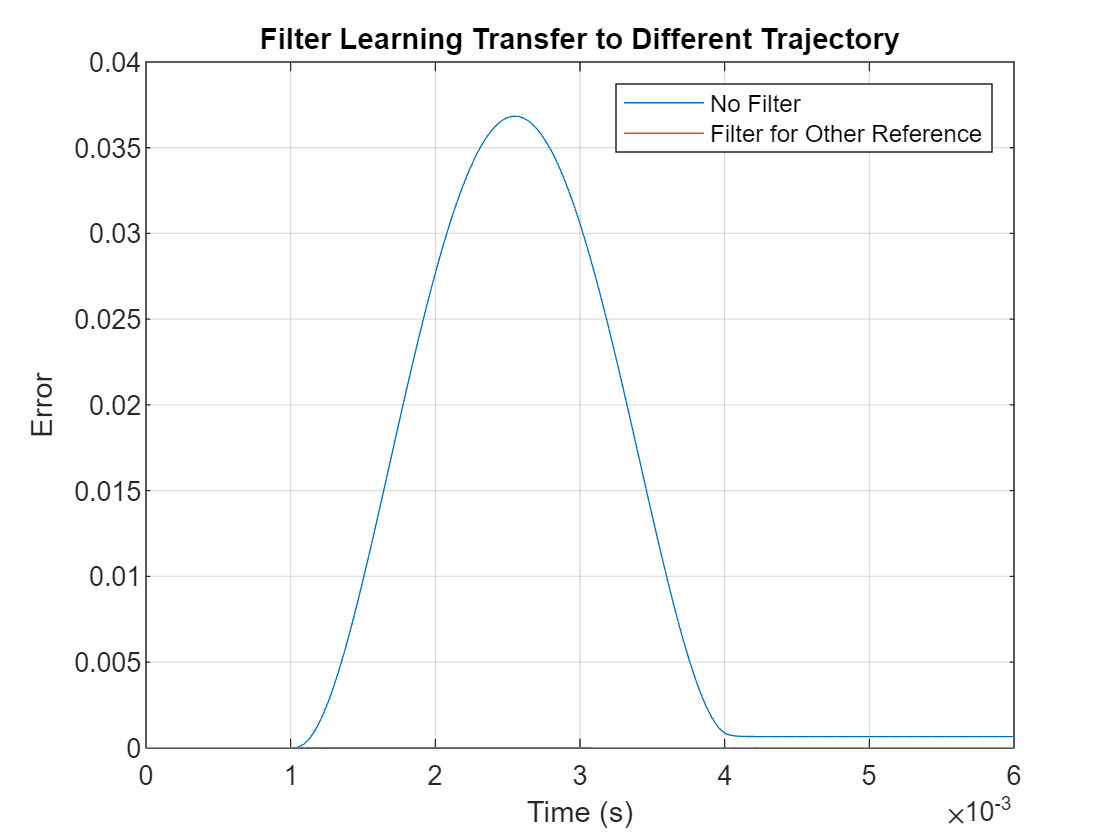

plot(tvec,[e_nofilt,e_filt])
title('Filter Learning Transfer to Different Trajectory')
legend('No Filter','Filter for Other Reference')
grid
xlabel('Time (s)')
ylabel('Error')

## Comparing Results Between Methods

Note that below I am cutting the last several samples to eliminate the finite length effects in the reference.

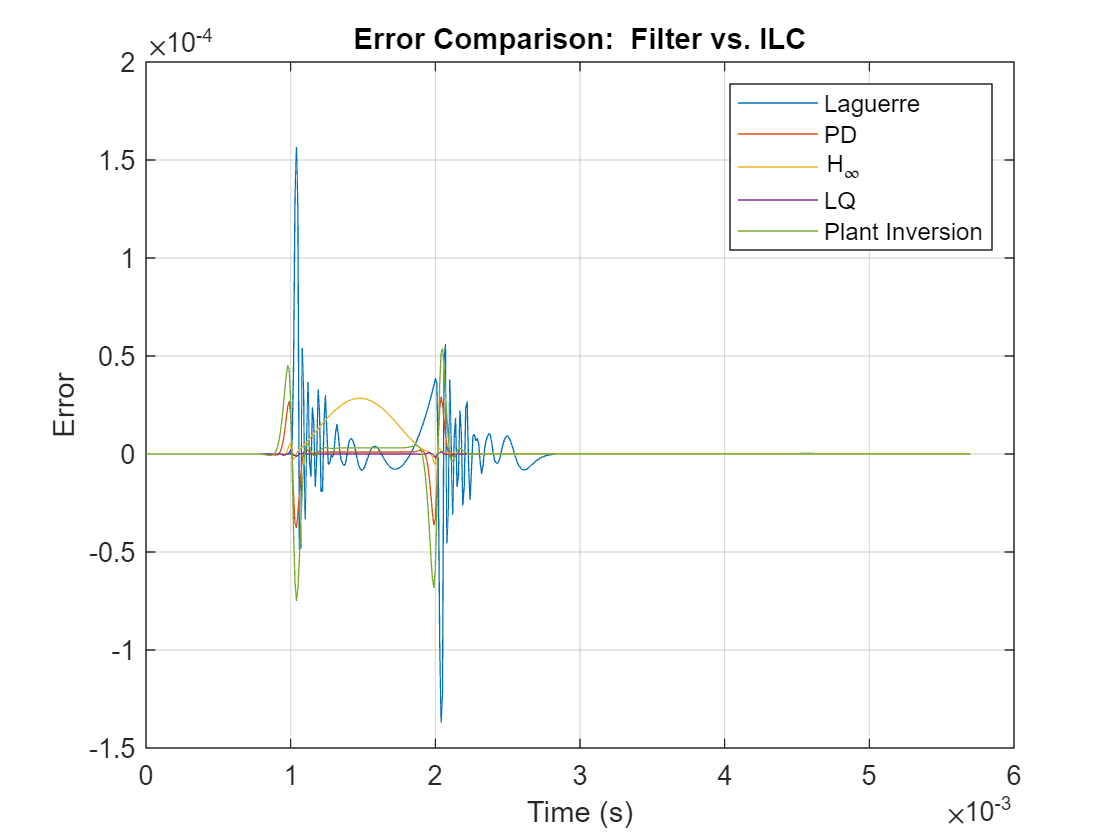

endchop = 30;
plot(tvec(1:end-endchop),[exLaguerre(1:end-endchop),exILC(1:end-endchop),exInf(1:end-endchop),exLQ(1:end-endchop),exInv(1:end-endchop,end)])
grid
legend('Laguerre','PD','H_\infty','LQ','Plant Inversion')
title('Error Comparison:  Filter vs. ILC')
xlabel('Time (s)')
ylabel('Error')

There is an obvious outlier here - the filter learning approach is just not as good.  That's because the other methods have hundreds of degrees of freedom, whereas the filter learning approach has only 20.  Still, it does pretty well, and its transferrability is particularly nice.

Let's look at the actual contenders.

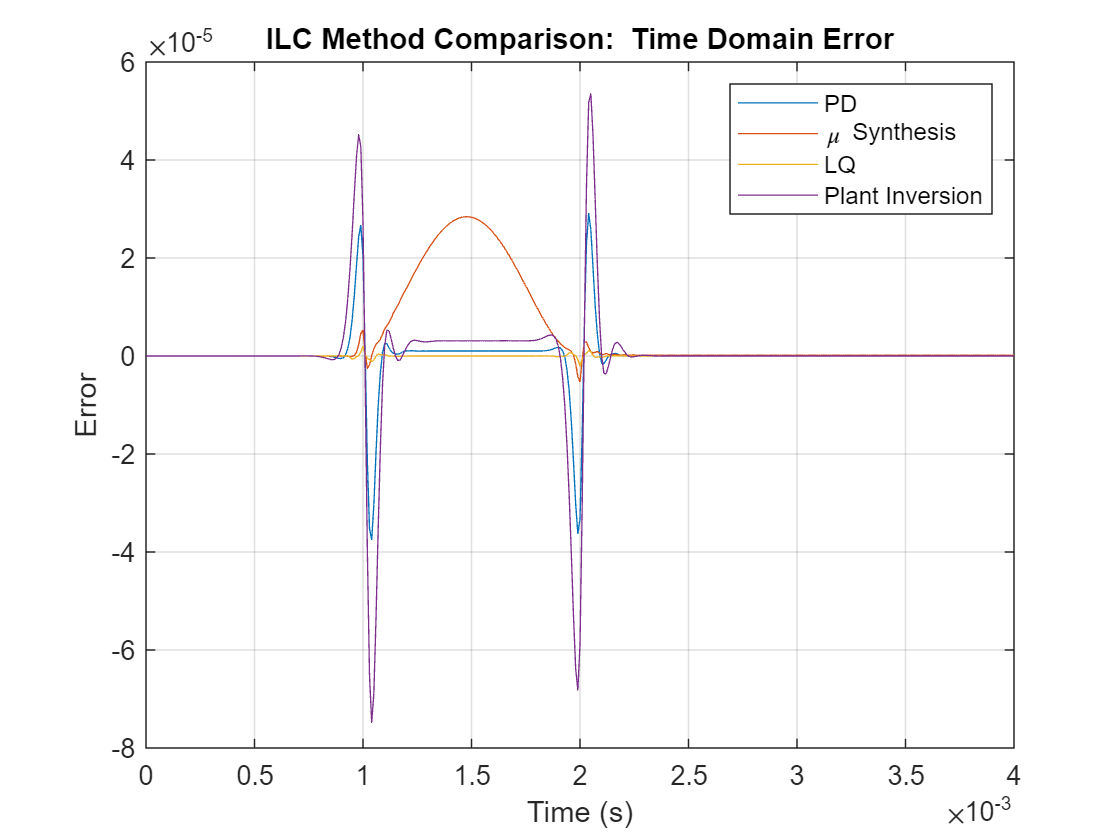

plot(tvec(1:end-endchop), [exILC(1:end-endchop),exInf(1:end-endchop),exLQ(1:end-endchop),exInv(1:end-endchop,end)])
legend('PD','\mu Synthesis','LQ','Plant Inversion')
grid
xlim([0,4e-3])
title('ILC Method Comparison:  Time Domain Error')
xlabel('Time (s)')
ylabel('Error')

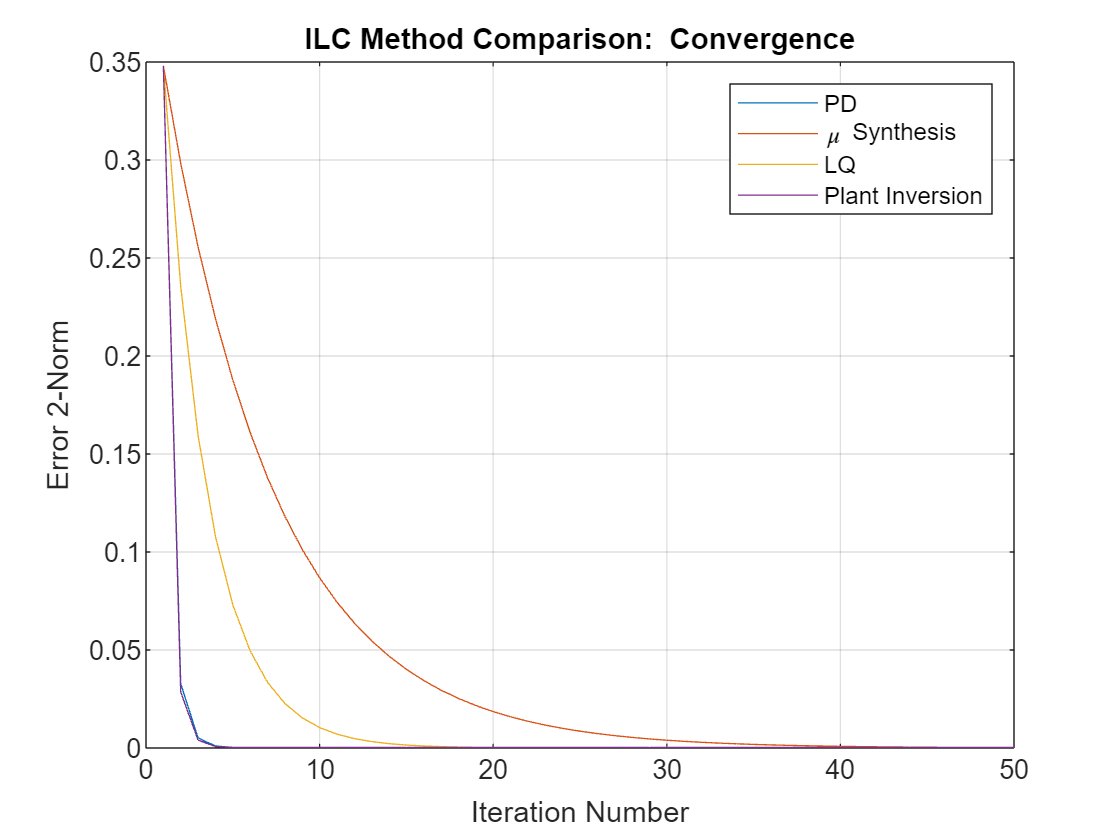

plot([enormILC',enormInf',enormLQ',enormInv'])
grid
legend('PD','\mu Synthesis','LQ','Plant Inversion')
title('ILC Method Comparison:  Convergence')
xlabel('Iteration Number')
ylabel('Error 2-Norm')

## Effects of Saturation

Here we will look at what happens to PD ILC when we have saturation.

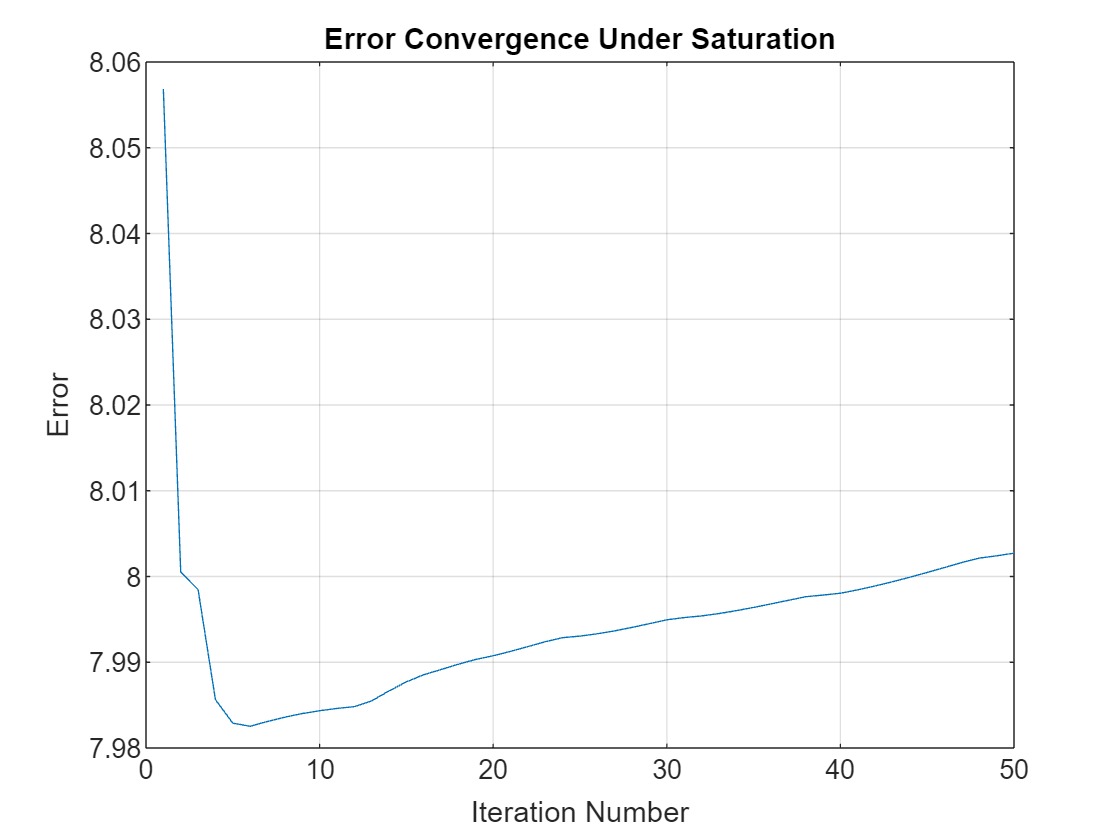

uff = zeros(length(r),1);
Kp = 1;  %The DC gain of the complementary sensitivity function is 1, so this is the inverse.
Kd = 3;  %I chose this to maximum the Q filter bandwidth
[bq,aq] = butter(2,65000/2/pi*2/Fs);  %Arbitrarily chose a 2nd order Butterworth
Q = tf(bq,aq,Ts);
ex = [];
enorm = [];
for ii = 1:Nit
    ex = [ex,ILCSimulation(r,uff,plantDT,K)'];
    enorm = [enorm,norm(ex(:,ii))];
    uff = filtfilt(bq,aq,uff+Kp*ex(:,ii)+Kd*[diff(ex(:,ii));0]);
end
plot(enorm)
grid
xlabel('Iteration Number')
ylabel('Error')
title('Error Convergence Under Saturation')

function errorOut = ILCSimulation(reference,uILC,Pd,C)
satLimit = 0.01;
[Ap,Bp,Cp,Dp] = ssdata(ss(Pd));
[Ac,Bc,Cc,Dc] = ssdata(ss(C));
y = 0;
errorOut = [];
xp = zeros(size(Ap,1),1);
xc = zeros(size(Ac,1),1);
for ii = 1:length(reference);
    y = Cp*xp;
    errorOut(ii) = reference(ii)-y;
    refIn = errorOut(ii)+uILC(ii);
    u = Cc*xc+Dc*refIn;
    if u>satLimit
        u = satLimit;
    elseif u<-satLimit
        u = -satLimit;
    end
    xp = Ap*xp+Bp*u;
    xc = Ac*xc+Bc*refIn;
end
end